## Chapter 2: PID controller

### 2.1 Traditional PID controller

clear all;
close all;
ts = 0.001; % sampling time

% Plant to control Gp(s) = 523500/(s^3 + 87.35s^2 + 10470s)
sys = tf(523500, [1 87.35 10470 0]);

dsys = c2d(sys,ts,'z') % Discrete the plant

dsys =
 
  8.533e-05 z^2 + 0.0003338 z + 8.169e-05
  ---------------------------------------
    z^3 - 2.906 z^2 + 2.823 z - 0.9164
 
Sample time: 0.001 seconds
Discrete-time transfer function.
Model Properties


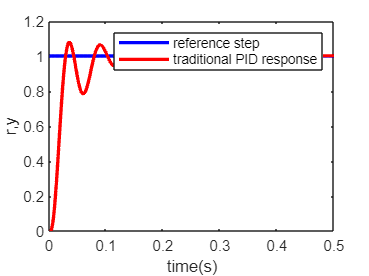

[num,den] = tfdata(dsys,'v');

% initial conditions
u_1 = 0;u_2 = 0;u_3 = 0;u_4 = 0;
y_1 = 0;y_2 = 0; y_3 = 0;
ei = 0;

% Parameters of PID controller

kp = 0.96;ki = 0.03;kd = 0.01;

error_1 = 0;

for k = 1:500

    time(k) = k*ts; % time of computation of response

    % Discrete response is equal to
    yd(k) = 1.0;
    y(k) = -den(2)*y_1 - den(3)* y_2 - den(4)*y_3 + num(1)*u_1 + num(2)*u_2 + num(3)*u_3 + num(4)*u_4;

    % Calculation of P
    error(k) = yd(k) - y(k);
    
    % Calculation of D
    derror(k) = error(k) - error_1;
    
    % Calculation of I
    ei = ei + error(k)*ts;

   % PID Controller
    u(k) = kp*error(k) +kd*derror(k)/ts+ki*ei;
    
    % Actualize the inputs and outputs
    u_4=u_3;u_3=u_2;u_2=u_1;u_1=u(k);
    y_3=y_2;y_2=y_1;y_1=y(k);
    error_1 = error(k);
end

% Plot step response
figure(1);
plot(time,yd,'b',time,y,'r','linewidth',2);
xlabel('time(s)');ylabel('r,y');
legend('reference step','traditional PID response')

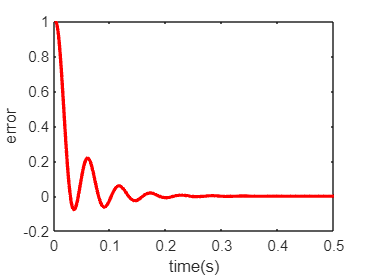

figure(2);
plot(time,yd-y,'r','linewidth',2);
xlabel('time(s)');ylabel('error');

### 2.2 Expert PID control

clear all;
close all;
ts = 0.001; % sampling time

% Plant to control Gp(s) = 523500/(s^3 + 87.35s^2 + 10470s)
sys = tf(523500, [1 87.35 10470 0]);

dsys = c2d(sys,ts,'z') % Discrete the plant

dsys =
 
  8.533e-05 z^2 + 0.0003338 z + 8.169e-05
  ---------------------------------------
    z^3 - 2.906 z^2 + 2.823 z - 0.9164
 
Sample time: 0.001 seconds
Discrete-time transfer function.
Model Properties


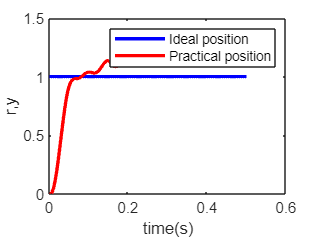

[num,den] = tfdata(dsys,'v');

% initial conditions
u_1 = 0;u_2 = 0;u_3 = 0;u_4 = 0;
y_1 = 0;y_2 = 0; y_3 = 0;
ei = 0;

% Parameters of PID controller

kp = 0.6;ki = 0.03;kd = 0.01;

error_1 = 0; derror_1 = 0;

for k = 1:500

    time(k) = k*ts; % time of computation of response

    % Discrete response is equal to
    yd(k) = 1.0;
    y(k) = -den(2)*y_1 - den(3)* y_2 - den(4)*y_3 + num(1)*u_1 + num(2)*u_2 + num(3)*u_3 + num(4)*u_4;

    % Calculation of P
    error(k) = yd(k) - y(k);
    
    % Calculation of D
    derror(k) = error(k) - error_1;
    
    % Calculation of I
    ei = ei + error(k)*ts;

   % PID Controller
    u(k) = kp*error(k) +kd*derror(k)/ts+ki*ei;
    
    % Expert control rules

    % Rule 1: use unloop controller to minimize quickly the error
    if abs(error(k)) > 0.8
        u(k) = 0.45;
    elseif abs(error(k)) > 0.4
        u(k) = 0.4;
    elseif abs(error(k)) > 0.2
        u(k) = 0.12;
    elseif abs(error(k)) > 0.01
        u(k) = 0.1;
    end

    % Rule 2: Condition on error
    if error(k)*derror(k) > 0 | (derror(k) == 0)
        M2 = 0.05;
        if abs(error(k)) >= M2
            % use strong P controller (k1 > 1)
            u(k) = u_1 + 2*(kp*(derror(k)) + ki*error(k) + kd*(derror(k) - derror_1));
        else
            % use weak P controller (1 > k1 > 0)
            u(k) = u_1 + (kp*(derror(k)) + ki*error(k) + kd*(derror(k) - derror_1));
        end
    end


     % Rule 2: Condition on error
    %if error(k)*derror(k)>0|(derror(k)==0) %Rule2
    %   if abs(error(k))>=0.05
    %       u(k)=u_1+2*kp*error(k);
    %   else
    %       u(k)=u_1+0.4*kp*error(k);
    %   end
    % end

    % Rule 3: Condition on error
    if ((error(k)*derror(k) < 0) & (derror(k)*derror_1 > 0))  | (error(k) == 0)
        u(k) = u(k);
    end

    % Rule 4: Condition on error
    if ((error(k)*derror(k) < 0) & (derror(k)*derror_1 < 0))
        M2 = 0.05;
        if abs(error(k)) >= M2
            % use strong P controller (k1 > 1)
            u(k) = u_1 + 2*kp*error(k);
        else
            % use weak P controller (1 > k1 > 0)
            u(k) = u_1 + 0.6*kp*error(k);
        end
    end

    % Rule 5: use PI Controller to decrease static error
    if abs(error(k)) <= 0.001
        u(k) = 0.5*error(k) + 0.01*ei;
    end

    % Actualize the inputs and outputs
    u_4=u_3;u_3=u_2;u_2=u_1;u_1=u(k);
    y_3=y_2;y_2=y_1;y_1=y(k);
    error_1 = error(k);
    derror_1 = derror(k); 
end

% Plot step response
figure(1);
plot(time,yd,'b',time,y,'r','linewidth',2);
xlabel('time(s)');ylabel('r,y');
legend('Ideal position','Practical position')

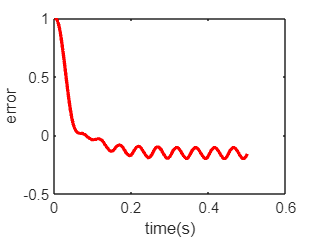

figure(2);
plot(time,yd-y,'r','linewidth',2);
xlabel('time(s)');ylabel('error');

## Chapter 3: Foundation of fuzzy Mathematics

### 3.1 Fuzzy set expression

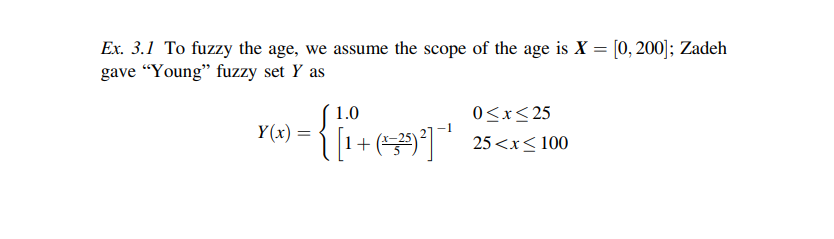

imshow(imread("fuzzy_age.png"));

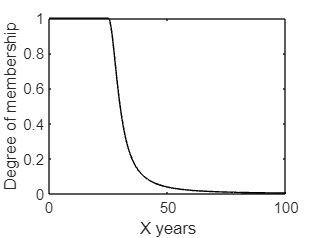


% Membership function for young people
clear all
close all

for k = 1:1001
    x(k) = (k-1)*0.1;
    if x(k) >= 0 & x(k)<= 25
        y(k) = 1.0;
    else
        y(k) = 1/(1 + ((x(k) - 25)/5)^2);
    end
end

plot(x,y,'k');
xlabel("X years");
ylabel('Degree of membership');

### 3.2 Typical membership functions

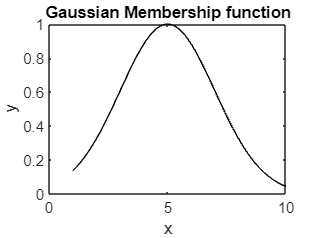

% Gaussian Membership function
x = 1:0.1:10;
c = 5;
delta = 2;
y = gaussmf(x,[delta c]);
plot(x,y,'k');
xlabel('x');ylabel('y');
title('Gaussian Membership function');

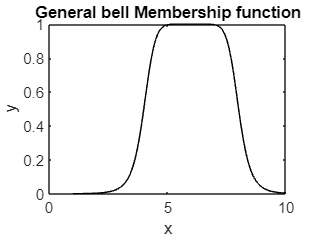


% General bell membership function

x = 1:0.1:10;
a = 2;
b = 4;
c = 6;
y = gbellmf(x,[a b c]);
plot(x,y,'k');
xlabel('x');ylabel('y');
title('General bell Membership function');

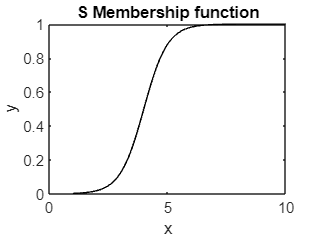



% S membership function

x = 1:0.1:10;
a = 2;
c = 4;
y = sigmf(x,[a c]);
plot(x,y,'k');
xlabel('x');ylabel('y');
title('S Membership function');

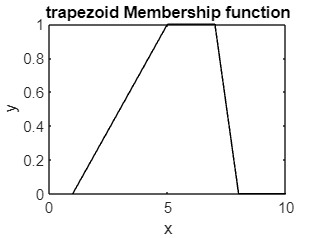


% trapezoid membership function

x = 1:0.1:10;
a = 1;
b = 5;
c = 7;
d = 8;
y = trapmf(x,[a b c d]);
plot(x,y,'k');
xlabel('x');ylabel('y');
title('trapezoid Membership function');

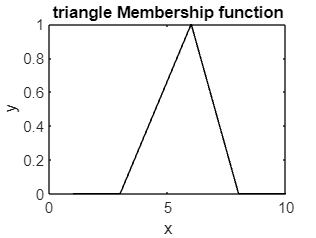


% Triangle membership function

x = 1:0.1:10;
a = 3;
b = 6;
c = 8;
y = trimf(x,[a b c]);
plot(x,y,'k');
xlabel('x');ylabel('y');
title('triangle Membership function');

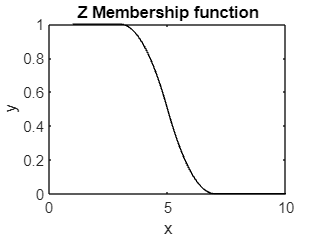


% Z membership function

x = 1:0.1:10;
a = 3;
b = 7;
y = zmf(x,[a b]);
plot(x,y,'k');
xlabel('x');ylabel('y');
title('Z Membership function');

### 3.3 Design of fuzzy system

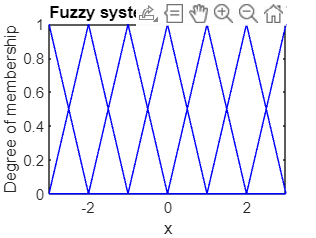

% To fuzzify a variable, we can use several fuzzy sets
% For example, to describe the error from big negative to big positive with
% 7 fuzzy sets, we define the error as e = {NB, NM, NS, ZO, PS, PM, PB}
% Use triangle MF and consider variable e varies in the range [-3,3]

% Define N+1 triangle membership function
clear all;
close all;

N = 6;
x = -3:0.01:3;

for i = 1:N+1
    f(i) = -3 + 6/N*(i-1);
end
% f = [-3 -2 -1 0 1 2 3]

u = trimf(x,[f(1),f(1),f(2)]);
figure(1);
plot(x,u,'b');
axis([-3 3 0 1])
hold on

for j = 2:N
    u = trimf(x,[f(j-1),f(j),f(j+1)]);
    plot(x,u,'b');
end

u = trimf(x,[f(N),f(N+1),f(N+1)]);
plot(x,u,'b');

xlabel('x');
ylabel('Degree of membership');
title('Fuzzy system with triangle MF');

hold off

### 3.4 fuzzy matrix compound calculation

clear all;
close all;

A = [0.8 0.7
    0.5 0.3];
sz_A = size(A);

B = [0.2 0.4
    0.6 0.9];
sz_B = size(B);

% Compound of A and B
for i = 1:sz_A(1)
    for j = 1:sz_B(1)
        C(i,j) = max(min(A(i,:),B(:,j)'));
    end
end

'Compound of A and B'

ans = 'Compound of A and B'

C

C =     0.6000    0.7000
    0.3000    0.4000



% Compound of B and A
for i = 1:sz_B(1)
    for j = 1:sz_A(1)
        D(i,j) = max(min(B(i,:),A(:,j)'));
    end
end

'Compound of B and A'

ans = 'Compound of B and A'

D

D =     0.4000    0.3000
    0.6000    0.6000


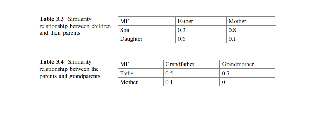


% The compound calculation of fuzzy matrix permits to compute the
% similarity between two elements when we have two matrices that describe the
% similarity between elements and they have the same elements in lines and columns

% Example

imshow(imread("similarity_relationship_matrices.png"));


% R is the similarity relationship between children and their parents
R = [0.2 0.8
    0.6 0.1];

% S is the similarity relationship between parents and grandparents
S = [0.5 0.7
    0.1 0];

% The similarity relationship between children and grandparents is
% described by the compound calculation between R and S

% Compound of R and S
sz_R = size(R);
sz_S = size(S);

for i = 1:sz_R(1)
    for j = 1:sz_S(1)
        RoS(i,j) = max(min(R(i,:),S(:,j)'));
    end
end

'Compound of R and S'

ans = 'Compound of R and S'

RoS

RoS =     0.2000    0.2000
    0.5000    0.6000


### 3.5 Fuzzy inference

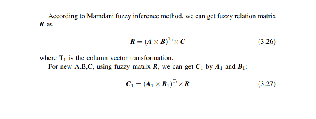

% Consider the rule "If A and B then C

clear all; close all

imshow(imread("fuzzy_inference.png"));


A = [0.5 1 0.1]';

B = [0.1 1 0.6];

C = [0.4 1];

% Compound of A and B

for i = 1:length(A)
    for j = 1:length(B)
        AoB(i,j) = min(A(i),B(j));
    end
end

'Compound between A and B'

ans = 'Compound between A and B'

AoB

AoB =     0.1000    0.5000    0.5000
    0.1000    1.0000    0.6000
    0.1000    0.1000    0.1000



% Column vector transformation
T1 = [];

for i = 1:length(A)
    T1 = [T1;AoB(i,:)'];
end

% Get fuzzy relation matrix R
for i = 1:length(T1)
    for j = 1:length(C)
        R(i,j) = min(T1(i),C(j));
    end
end

'Fuzzy relation matrix R'

ans = 'Fuzzy relation matrix R'

R

R =     0.1000    0.1000
    0.4000    0.5000
    0.4000    0.5000
    0.1000    0.1000
    0.4000    1.0000
    0.4000    0.6000
    0.1000    0.1000
    0.1000    0.1000
    0.1000    0.1000



% New matrices A1 and B1 and C1

A1 = [1 0.5 0.1]';

B1 = [0.1 0.5 1];

% Compound of A1 and B1

for i = 1:length(A1)
    for j = 1:length(B1)
        A1oB1(i,j) = min(A1(i),B1(j));
    end
end

'Compound between A1 and B1'

ans = 'Compound between A1 and B1'

A1oB1

A1oB1 =     0.1000    0.5000    1.0000
    0.1000    0.5000    0.5000
    0.1000    0.1000    0.1000



% raw vector transformation
T2 = [];

for i = 1:length(A1)
    T2 = [T2 A1oB1(i,:)];
end

% Get output C1
sz_R = size(R)

sz_R =      9     2


for i = 1:length(T2)
    for j = 1:sz_R(2)
        D(i,j) = min(T2(i),R(i,j));
        C1(j) = max(D(:,j));
    end
end

'Output C1'

ans = 'Output C1'

C1

C1 =     0.4000    0.5000



% so C1 = 0.4/c1 + 0.5/c2

## Chapter 4: Fuzzy Logic Control

### 4.1 Design of Fuzzy Logic Controller for height water tank

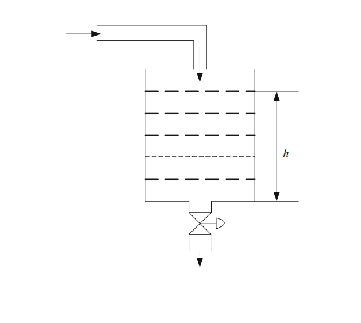

% Fuzzy control for a height level of water tank
clear all; close all; warning off

imshow(imread("height_level_water_tank.png"));

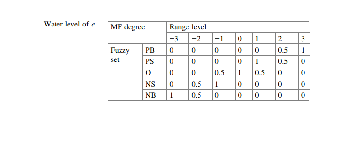


a = newfis('fuzz_tank');

%% (1) Fuzzify input and output

% Parameter of error e

imshow(imread("water_level_e.png"));

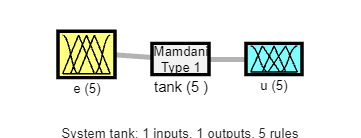


a = addvar(a,'input','e',[-3,3]);
a = addmf(a,'input',1,'NB','zmf',[-3,-1]);
a = addmf(a,'input',1,'NS','trimf',[-3,-1,1]);
a = addmf(a,'input',1,'Z','trimf',[-2,0,2]);
a = addmf(a,'input',1,'PS','trimf',[-1,1,3]);
a = addmf(a,'input',1,'PB','smf',[1,3]);

% Parameter of control u

imshow(imread("control_u.png"));

a = addvar(a,'output','u',[-4,4]);
a = addmf(a,'output',1,'NB','zmf',[-4,-1]);
a = addmf(a,'output',1,'NS','trimf',[-4,-2,1]);
a = addmf(a,'output',1,'Z','trimf',[-2,0,2]);
a = addmf(a,'output',1,'PS','trimf',[-1,2,4]);
a = addmf(a,'output',1,'BP','smf',[1 4]);

%% (2) Edit rule base

rulelist = [1 1 1 1
    2 2 1 1
    3 3 1 1
    4 4 1 1
    5 5 1 1];

a = addrule(a,rulelist);

% (3) Defuzzy

a1 = setfis(a,'DefuzzMethod','mom');

% Save to fuzzy filz "tank.fis"
writefis(a1,'tank');
a2 = readfis('tank');

% Plot system of tank and fuzzy system of input e and output u
figure(1)
plotfis(a2);

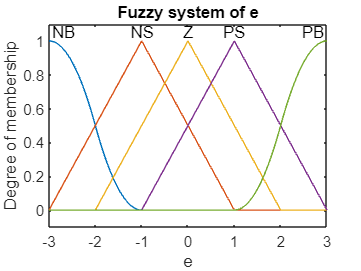

figure(2)
plotmf(a,'input',1);
title('Fuzzy system of e');

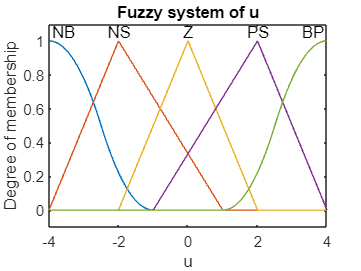

figure(3)
plotmf(a,'output',1);
title('Fuzzy system of u');


flag = 1

flag = 1

ans = 5×34 char array
    '1. If (e is NB) then (u is NB) (1)'
    '2. If (e is NS) then (u is NS) (1)'
    '3. If (e is Z) then (u is Z) (1)  '
    '4. If (e is PS) then (u is PS) (1)'
    '5. If (e is PB) then (u is BP) (1)'


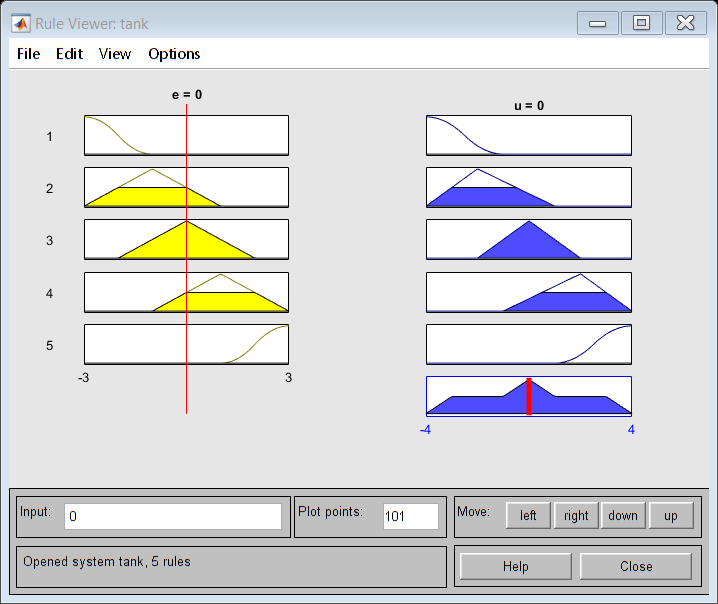

if flag == 1
    showrule(a) % Show fuzzy rule base
    ruleview('tank'); % Dynamic Simulation
end


disp('—————————————————————————————————————————————————————');

—————————————————————————————————————————————————————


disp(' fuzzy controller table:e=[-3,+3],u=[-4,+4] ');

 fuzzy controller table:e=[-3,+3],u=[-4,+4] 


disp('—————————————————————————————————————————————————————');

—————————————————————————————————————————————————————



for i = 1:7
    e(i) = i-4;
    Ulist(i) = evalfis([e(i)],a2);
end
Ulist = round(Ulist)

Ulist =     -4    -2    -2     0     2     2     4



e = -3; % error
u = evalfis([e],a2) % using fuzzy inference

u = -4

### 4.2 Design of Fuzzy Logic Controller for Washing machine

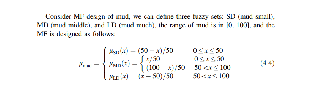

% Design a fuzzy controller with 2 inputs and 1 output
clear all; close all; warning off

% (1) define of membership functions

%% MF of mud

imshow(imread("MF_mud.png"));

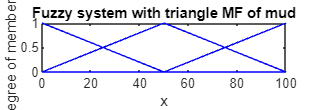


N = 2;

x = 0:0.1:100;

for i = 1:N+1
    f(i) = 100/N*(i-1);
end

% f = [0 50 100]

u = trimf(x,[f(1),f(1),f(2)]);
figure(1);
plot(x,u,'b');
axis([0 100 0 1])
hold on

for j = 2:N
    u = trimf(x,[f(j-1),f(j),f(j+1)]);
    plot(x,u,'b');
end

u = trimf(x,[f(N),f(N+1),f(N+1)]);
plot(x,u,'b');

xlabel('x');
ylabel('Degree of membership');
title('Fuzzy system with triangle MF of mud');

hold off

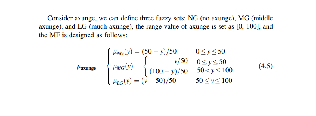


%% MF of axunge

imshow(imread("MF_axunge.png"));


N = 2;

x = 0:0.1:100;


for i = 1:N+1
    f(i) = 100/N*(i-1);
end
f

f =      0    50   100


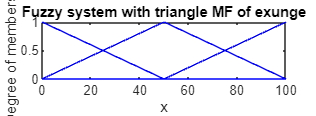

% f = [0 50 100]

u = trimf(x,[f(1),f(1),f(2)]);
figure(1);
plot(x,u,'b');
axis([0 100 0 1])
hold on

for j = 2:N
    u = trimf(x,[f(j-1),f(j),f(j+1)]);
    plot(x,u,'b');
end

u = trimf(x,[f(N),f(N+1),f(N+1)]);
plot(x,u,'b');

xlabel('x');
ylabel('Degree of membership');
title('Fuzzy system with triangle MF of exunge');

hold off

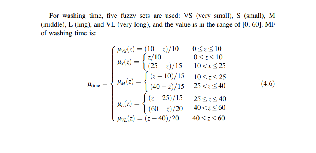


%% MF of washing time

imshow(imread("MF_washing_time.png"));

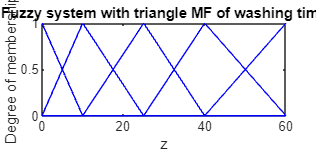


z = 0:0.1:60;

u = trimf(z,[0 0 10]);
figure(1);
plot(z,u,'b');

hold on

u = trimf(z,[0 10 25]);
plot(z,u,'b');

u = trimf(z,[10 25 40]);
plot(z,u,'b');

u = trimf(z,[25 40 60]);
plot(z,u,'b');

u = trimf(z,[40 60 60]);
plot(z,u,'b');

xlabel('z');
ylabel('Degree of membership');
title('Fuzzy system with triangle MF of washing time');
axis([0 60 0 1]);

hold off

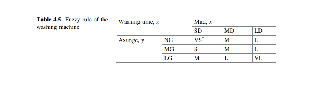


 % (2) fuzzy rule of the washing machine in respect of mud and axunge
imshow(imread("fuzzy_rule_washing_time_machine.png"));


% (3) fuzzy rule activation of the washing machine
imshow(imread("fuzzy_rule_activation.png"));

% Simulation of washing time

% Fuzzy control for a washing time

a = newfis('fuzz_wash');

%% (1) Fuzzify inputs and output

% Parameter of mud

a = addvar(a,'input','x',[0 100]);
a = addmf(a,'input',1,'SD','trimf',[0 0 50]);
a = addmf(a,'input',1,'MD','trimf',[0 50 100]);
a = addmf(a,'input',1,'LD','trimf',[50 100 100]);

% Parameter of exauge

a = addvar(a,'input','y',[0 100]);
a = addmf(a,'input',2,'NG','trimf',[0 0 50]);
a = addmf(a,'input',2,'MG','trimf',[0 50 100]);
a = addmf(a,'input',2,'LG','trimf',[50 100 100]);

% Parameter of washing time

a = addvar(a,'output','z',[0 60]);
a = addmf(a,'output',1,'VS','trimf',[0 0 10]);
a = addmf(a,'output',1,'S','trimf',[0 10 25]);
a = addmf(a,'output',1,'M','trimf',[10 25 40]);
a = addmf(a,'output',1,'L','trimf',[25 40 60]);
a = addmf(a,'output',1,'VL','trimf',[40 60 60]);

%% (2) Edit rule base

rulelist=[1 1 1 1 1; 
1 2 3 1 1;
1 3 4 1 1;
2 1 2 1 1;
2 2 3 1 1;
2 3 4 1 1;
3 1 3 1 1;
3 2 4 1 1;
3 3 5 1 1];

a = addrule(a,rulelist);
showrule(a) % Show fuzzy rule base

ans = 9×48 char array
    '1. If (x is SD) and (y is NG) then (z is VS) (1)'
    '2. If (x is SD) and (y is MG) then (z is M) (1) '
    '3. If (x is SD) and (y is LG) then (z is L) (1) '
    '4. If (x is MD) and (y is NG) then (z is S) (1) '
    '5. If (x is MD) and (y is MG) then (z is M) (1) '
    '6. If (x is MD) and (y is LG) then (z is L) (1) '
    '7. If (x is LD) and (y is NG) then (z is M) (1) '
    '8. If (x is LD) and (y is MG) then (z is L) (1) '
    '9. If (x is LD) and (y is LG) then (z is VL) (1)'


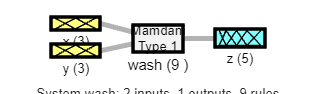


% (3) Defuzzy

a1 = setfis(a,'DefuzzMethod','mom');

% Save to fuzzy file "wash.fis"
writefis(a1,'wash');
a2 = readfis('wash');

% Plot system of washing time and fuzzy system of inputs mud and axunge and
% output washing time
figure(1)
plotfis(a2);

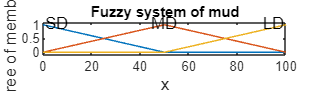

figure(2)
plotmf(a,'input',1);
title('Fuzzy system of mud');

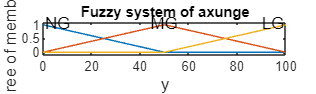

figure(3)
plotmf(a,'input',2);
title('Fuzzy system of axunge');

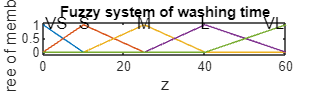

figure(4)
plotmf(a,'output',1);
title('Fuzzy system of washing time');


x = 60;
y = 70;
evalfis([x,y],a2)

ans = 24.9000

### 4.3 Design of Fuzzy Logic Controller for PI controller

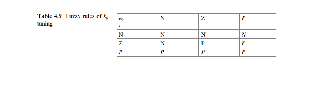

% Design a fuzzy controller for PI controller with 2 inputs and 2 outputs
% (kp and ki)
clear all; close all;warning off

%% fuzzy rules for kp

imshow(imread("fuzzy_rules_kp.png"));


%% fuzzy rules for ki

imshow(imread("fuzzy_rules_ki.png"));

% Simulation of PI controller

a = newfis('fuzz_wash');

%% (1) Fuzzify inputs and output

% Parameter of error

a = addvar(a,'input','e',[-1 1]);
a = addmf(a,'input',1,'N','zmf',[-1 -1/3]);
a = addmf(a,'input',1,'Z','trimf',[-2/3 0 2/3]);
a = addmf(a,'input',1,'P','smf',[1/3 1]);

% Parameter of error change

a = addvar(a,'input','ec',[-1 1]);
a = addmf(a,'input',2,'N','zmf',[-1 -1/3]);
a = addmf(a,'input',2,'Z','trimf',[-2/3 0 2/3]);
a = addmf(a,'input',2,'P','smf',[1/3 1]);

% Parameter of kp

a = addvar(a,'output','kp',1/3 * [-10 10]);
a = addmf(a,'output',1,'N','zmf',1/3 * [-10 -3]);
a = addmf(a,'output',1,'Z','trimf',1/3 * [-5 0 5]);
a = addmf(a,'output',1,'P','smf',1/3 * [3 10]);

% Parameter of ki

a = addvar(a,'output','ki',1/30 * [-3 3]);
a = addmf(a,'output',2,'N','zmf',1/30 * [-3 -1]);
a = addmf(a,'output',2,'Z','trimf',1/30 * [-2 0 2]);
a = addmf(a,'output',2,'P','smf',1/3 * [1 3]);

%% (2) Edit rule base

rulelist=[1 1 1 2 1 1;
1 2 1 2 1 1;
1 3 1 2 1 1;
2 1 1 3 1 1;
2 2 3 3 1 1;
2 3 3 3 1 1;
3 1 3 2 1 1;
3 2 3 2 1 1;
3 3 3 2 1 1];

a = addrule(a,rulelist);
showrule(a) % Show fuzzy rule base

ans = 9×56 char array
    '1. If (e is N) and (ec is N) then (kp is N)(ki is Z) (1)'
    '2. If (e is N) and (ec is Z) then (kp is N)(ki is Z) (1)'
    '3. If (e is N) and (ec is P) then (kp is N)(ki is Z) (1)'
    '4. If (e is Z) and (ec is N) then (kp is N)(ki is P) (1)'
    '5. If (e is Z) and (ec is Z) then (kp is P)(ki is P) (1)'
    '6. If (e is Z) and (ec is P) then (kp is P)(ki is P) (1)'
    '7. If (e is P) and (ec is N) then (kp is P)(ki is Z) (1)'
    '8. If (e is P) and (ec is Z) then (kp is P)(ki is Z) (1)'
    '9. If (e is P) and (ec is P) then (kp is P)(ki is Z) (1)'


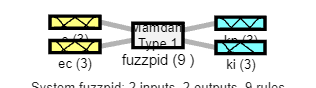

ruleview fuzzpid

% (3) Defuzzy

a1 = setfis(a,'DefuzzMethod','mom');

% Save to fuzzy file "fuzzpid.fis"
writefis(a1,'fuzzpid');
a2 = readfis('fuzzpid');

% Plot system of PI and fuzzy system of inputs error and change of error and
% 2 outputs kp and ki
figure(1)
plotfis(a2);

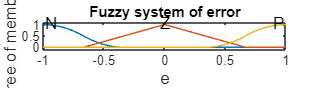

figure(2)
plotmf(a,'input',1);
title('Fuzzy system of error');

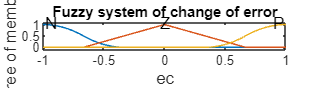

figure(3)
plotmf(a,'input',2);
title('Fuzzy system of change of error');

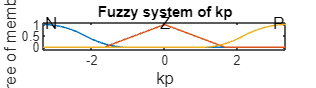

figure(4)
plotmf(a,'output',1);
title('Fuzzy system of kp');

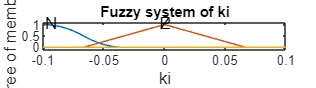

figure(5)
plotmf(a,'output',2);
title('Fuzzy system of ki');

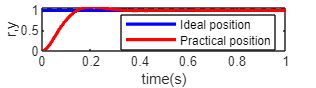


%% Fuzzy PI control
warning off

ts = 0.001; % sampling time
sys = tf(133, [1,25,0]); % transfer function of plant G(s) = 133/(s^2 + 25s)
dsys = c2d(sys,ts,'z');
[num,den] = tfdata(dsys,'v');
u_1 = 0;u_2 = 0;
y_1 = 0;y_2 = 0;
e_1 = 0;ec_1 = 0;ei = 0;
kp0 = 0;ki0 = 0;

for k = 1:1000
    time(k) = k*ts;
    yd(k) = 1;
    % fuzzy inference to tuning PI
    k_pid = evalfis([e_1,ec_1],a2);
    kp(k) = kp0 + k_pid(1);
    ki(k) = ki0 + k_pid(2);
    u(k) = kp(k)*e_1 + ki(k)*ei;
    y(k) = -den(2)*y_1 - den(3)*y_2 + num(2)*u_1 + num(3)*u_2;
    e(k) = yd(k) - y(k);

    % Actualize of input and output parameters of transfer function
    u_2 = u_1; u_1 = u(k);
    y_2 = y_1; y_1 = y(k);
    ei = ei + e(k)*ts; % Calculating of I action
    ec(k) = e(k) - e_1;
    e_1 = e(k);
    ec_1 = ec(k);
end

% Plot step response
figure(1);
plot(time,yd,'b',time,y,'r','linewidth',2);
xlabel('time(s)');ylabel('r,y');
legend('Ideal position','Practical position')

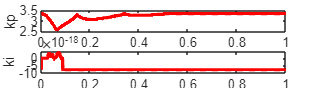

figure(2);
subplot(211);
plot(time,kp,'r','linewidth',2);
xlabel('time(s)');ylabel('kp');
subplot(212);
plot(time,ki,'r','linewidth',2);
xlabel('time(s)');ylabel('ki');

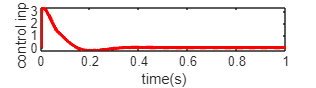


clf

figure(3);
plot(time,u,'r','linewidth',2);
xlabel('time(s)');ylabel('control input');

## Chapter 5: Fuzzy Takagi-Sugeno (T-S) Modeling and control

### 5.1 Simulation of a simple T-S type fuzzy model

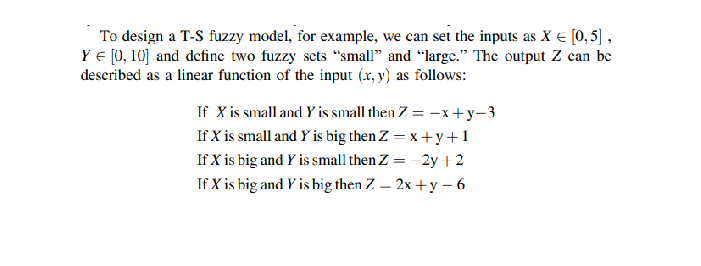

clear all; close all; warning off

% The fuzzy Takagi-Sugeno model to design
imshow(imread("design_simple_TS_fuzzy_model.png"));


% Build architucture of TS fuzzy model

ts2 = newfis('ts2','sugeno');
ts2 = addvar(ts2,'input', 'X',[0 5]);
ts2 = addmf(ts2,'input',1,'little','gaussmf',[1.8 0]);
ts2 = addmf(ts2,'input',1,'big','gaussmf',[1.8 5]);
ts2 = addvar(ts2,'input', 'Y',[0 10]);
ts2 = addmf(ts2,'input',2,'little','gaussmf',[4.4 0]);
ts2 = addmf(ts2,'input',2,'big','gaussmf',[4.4 10]);
ts2 = addvar(ts2,'output', 'z',[-3 15]);
ts2 = addmf(ts2,'output',1,'first area','linear',[-1 1 -3]);
ts2 = addmf(ts2,'output',1,'second area','linear',[1 1 1]);
ts2 = addmf(ts2,'output',1,'third area','linear',[0 -2 2]);
ts2 = addmf(ts2,'output',1,'fourth area','linear',[2  1 -6]);

% Rules
rulelist = [1 1 1 1 1
    1 2 2 1 1
    2 1 3 1 1
    2 2 4 1 1];
ts2 = addrule(ts2,rulelist);
showrule(ts2)

ans = 4×64 char array
    '1. If (X is little) and (Y is little) then (z is first area) (1)'
    '2. If (X is little) and (Y is big) then (z is second area) (1)  '
    '3. If (X is big) and (Y is little) then (z is third area) (1)   '
    '4. If (X is big) and (Y is big) then (z is fourth area) (1)     '


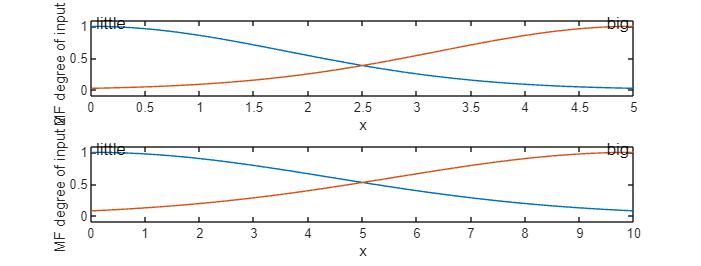


% Plot membership function of inputs

figure(1);
subplot(211);
plotmf(ts2,'input',1);
xlabel('x');
ylabel('MF degree of input 1');
subplot(212);
plotmf(ts2,'input',2);
xlabel('x');
ylabel('MF degree of input 2');

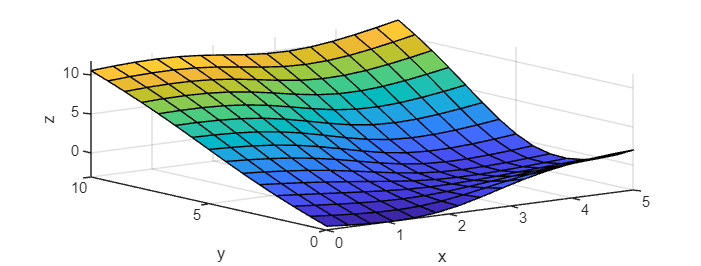


clf
figure(2);
gensurf(ts2);
xlabel('x');
ylabel('y');
zlabel('z');

### 5.2 Fuzzy T-S modeling and control based on Linear matrix inequality (LMI)

#### 5.2.1 Controller gain based on LMI for control of Inverted pendulum with 2 rules

clear all;close all;

% Physical constant of inverted pendulum
g = 9.8; % constant gravity in earth (m/s2)
m = 2; % mass of cart (kg)
M = 8; % mass of pendulum (kg)
l = 0.5; % half of length of pendulum (m)
a = 1/(M+m);
beta = cos(88*pi/180);

% State space representation for 2 rules selected

% rule 1: if x1 is about 0 then dx/dt = A1*x + B1*u
% rule 2: if abs(x1) is about pi/2 then dx/dt = A2*x + B2*u

beta=cos(88*pi/180);
a1=4*l/3-a*m*l;
A1=[0 1;g/a1 0];
B1=[0 ;-a/a1];
a2=4*l/3-a*m*l*beta^2;
A2=[0 1;2*g/(pi*a2) 0];
B2=[0;-a*beta/a2];


% LMI design with solution of Lyapunov equation
% Should install Robust Control Toolbox and  YALMIP toolbox following the
% url: https://yalmip.github.io/tutorial/installation/

Q = sdpvar(2,2);
V1 = sdpvar(1,2);
V2 = sdpvar(1,2);

L1=Q*A1'+A1*Q+V1'*B1'+B1*V1;
L2=Q*A2'+A2*Q+V2'*B2'+B2*V2;
L3=Q*A1'+A1*Q+Q*A2'+A2*Q+V2'*B1'+B1*V2+V1'*B2'+B2*V1;
F = [L1<=0];
F = [F,L2<=0];
F = [F ,L3<=0];
F = [F,Q>=0];

solvesdp(F); %To get Q,V1,V2


 Solver for LMI feasibility problems L(x) < R(x)
    This solver minimizes  t  subject to  L(x) < R(x) + t*I
    The best value of t should be negative for feasibility

 Iteration   :    Best value of t so far 
 
     1                        0.083653
     2                        0.044254
     3                        0.044254
     4                    2.198866e-03
     5                       -0.022577

 Result:  best value of t:    -0.022577
          f-radius saturation:  0.000% of R =  1.00e+09
 
#############################################################
You are using LMILAB. Please don't use LMILAB with YALMIP
https://yalmip.github.io/solver/lmilab/
 
Install a better SDP solver
https://yalmip.github.io/allsolvers/
 
To get rid of this message, edit calllmilab.m  
(but don't expect support when things do not work,
YALMIP + LMILAB => No support)
#############################################################



Q = double(Q);
V1 = double(V1);
V2 = double(V2);
P = inv(Q);
K1 = V1*P

K1 = 1.0e+03 *

    1.2432    0.3594


K2 = V2*P

K2 = 1.0e+03 *

    2.6328    0.7738


save K_file K1 K2


% membership function design

clear all;close all;
L1 =  -pi/2;
L2 = pi/2;
L = L2 - L1;
h = pi/2;
N = L/h;
T = 0.01;
x = L1:T:L2

x =    -1.5708   -1.5608   -1.5508   -1.5408   -1.5308   -1.5208   -1.5108   -1.5008   -1.4908   -1.4808   -1.4708   -1.4608   -1.4508   -1.4408   -1.4308   -1.4208   -1.4108   -1.4008   -1.3908   -1.3808   -1.3708   -1.3608   -1.3508   -1.3408   -1.3308   -1.3208   -1.3108   -1.3008   -1.2908   -1.2808   -1.2708   -1.2608   -1.2508   -1.2408   -1.2308   -1.2208   -1.2108   -1.2008   -1.1908   -1.1808   -1.1708   -1.1608   -1.1508   -1.1408   -1.1308   -1.1208   -1.1108   -1.1008   -1.0908   -1.0808


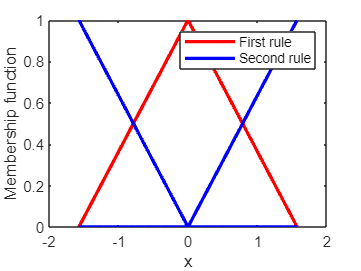


for i = 1:N+1
    e(i) = L1 + L/N*(i-1);
end

u = trimf(x,[e(1) e(2) e(3)]); % the middle MF
plot(x,u,'r','LineWidth',2);

for j=1:N
    if j == 1
        u = trimf(x,[e(1) e(1) e(2)]); % the first MF
    elseif j == N
        u = trimf(x,[e(N) e(N+1) e(N+1)]); % the last MF
    end
    hold on
    plot(x,u,'b','LineWidth',2);
end
xlabel('x');ylabel('Membership function');
legend('First rule','Second rule')

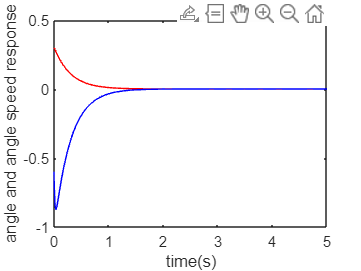

% First see and run simulink file sim_single_inverted_pendulum.slx

close all;

ut = out.ut;
x = out.x;
t = out.t;

figure(1);
plot(t,x(:,1),'r',t,x(:,2),'b');
xlabel('time(s)');ylabel('angle and angle speed response');

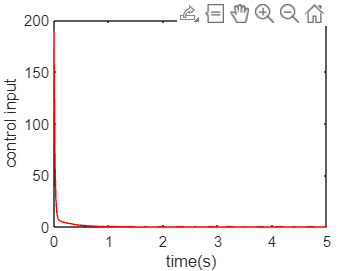


figure(2);
plot(t,ut(:,1),'r');
xlabel('time(s)');ylabel('control input');

#### 5.2.2 Controller gain based on LMI for control of Inverted pendulum with 4 rules

clear all;close all;

% Physical constant of inverted pendulum
g = 9.8; % constant gravity in earth (m/s2)
m = 2; % mass of cart (kg)
M = 8; % mass of pendulum (kg)
l = 0.5; % half of length of pendulum (m)
a = 1/(M+m);
beta = cos(88*pi/180);

% State space representation for 4 rules selected

% rule 1: if x1 is about 0 then dx/dt = A1*x + B1*u
% rule 2: if abs(x1) < pi/2 then dx/dt = A2*x + B2*u
% rule 3: if abs(x1) > pi/2 then dx/dt = A3*x + B3*u
% rule 4: if abs(x1) is about pi then dx/dt = A4*x + B4*u

beta=cos(88*pi/180);
a1=4*l/3-a*m*l;
A1=[0 1;g/a1 0];
B1=[0 ;-a/a1];
a2=4*l/3-a*m*l*beta^2;
A2=[0 1;2*g/(pi*a2) 0];
B2=[0;-a*beta/a2];
a3=pi*a2;
A3=[0 1;2*g/a3 0];
B3=[0 ;a*beta*pi/a3];
a4=4*l/3-a*m*l;
A4=[0 1;0 0];
B4=[0;a/a4];

% LMI design with solution of Lyapunov equation
% Should install Robust Control Toolbox and  YALMIP toolbox following the
% url: https://yalmip.github.io/tutorial/installation/

Q = sdpvar(2,2);
V1 = sdpvar(1,2);
V2 = sdpvar(1,2);
V3 = sdpvar(1,2);
V4 = sdpvar(1,2);

L1=Q*A1'+A1*Q+V1'*B1'+B1*V1;
L2=Q*A2'+A2*Q+V2'*B2'+B2*V2;
L3=Q*A3'+A3*Q+V3'*B3'+B3*V3;
L4=Q*A4'+A4*Q+V4'*B4'+B4*V4;
L5=Q*A1'+A1*Q+Q*A2'+A2*Q+V2'*B1'+B1*V2+V1'*B2'+B2*V1;
L6=Q*A3'+A3*Q+Q*A4'+A4*Q+V4'*B3'+B3*V4+V3'*B4'+B4*V3;
F = [L1<=0];
F = [F,L2<=0];
F = [F ,L3<=0];
F = [F ,L4<=0];
F = [F ,L5<=0];
F = [F ,L6<=0];
F = [F,Q>=0];

solvesdp(F); %To get Q,V1,V2,V3,V4


 Solver for LMI feasibility problems L(x) < R(x)
    This solver minimizes  t  subject to  L(x) < R(x) + t*I
    The best value of t should be negative for feasibility

 Iteration   :    Best value of t so far 
 
     1                        0.075650
     2                        0.042280
     3                        0.042280
     4                        0.012358
     5                       -0.011921

 Result:  best value of t:    -0.011921
          f-radius saturation:  0.000% of R =  1.00e+09
 
#############################################################
You are using LMILAB. Please don't use LMILAB with YALMIP
https://yalmip.github.io/solver/lmilab/
 
Install a better SDP solver
https://yalmip.github.io/allsolvers/
 
To get rid of this message, edit calllmilab.m  
(but don't expect support when things do not work,
YALMIP + LMILAB => No support)
#############################################################



Q = double(Q);
V1 = double(V1);
V2 = double(V2);
V3 = double(V3);
V4 = double(V4);
P = inv(Q);
K1 = V1*P

K1 = 1.0e+03 *

    1.7481    0.5154


K2 = V2*P

K2 = 1.0e+03 *

    3.3341    0.9891


K3 = V3*P

K3 = 1.0e+03 *

   -3.2455   -0.9911


K4 = V4*P

K4 = 1.0e+03 *

   -1.6500   -0.5154


save K_file2 K1 K2 K3 K4

% membership function design

L1 =  -pi;
L2 = pi;
L = L2 - L1;
h = pi/2;
N = L/h;
T = 0.01;
x = L1:T:L2

x =    -3.1416   -3.1316   -3.1216   -3.1116   -3.1016   -3.0916   -3.0816   -3.0716   -3.0616   -3.0516   -3.0416   -3.0316   -3.0216   -3.0116   -3.0016   -2.9916   -2.9816   -2.9716   -2.9616   -2.9516   -2.9416   -2.9316   -2.9216   -2.9116   -2.9016   -2.8916   -2.8816   -2.8716   -2.8616   -2.8516   -2.8416   -2.8316   -2.8216   -2.8116   -2.8016   -2.7916   -2.7816   -2.7716   -2.7616   -2.7516   -2.7416   -2.7316   -2.7216   -2.7116   -2.7016   -2.6916   -2.6816   -2.6716   -2.6616   -2.6516


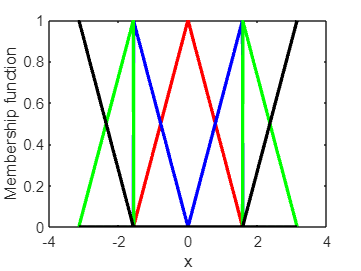


for i = 1:N+1
    e(i) = L1 + L/N*(i-1);
end

figure(2)

h1 = trimf(x,[e(2) e(3) e(4)]); % rule1: x1 is to zero
plot(x,h1,'r','LineWidth',2);

hold on

h2 = trimf(x,[e(2) e(2) e(3)]); % rule2 : x1 is to -pi/2 but higher
plot(x,h2,'b','LineWidth',2);

h2 = trimf(x,[e(3) e(4) e(4)]); % rule2 : x1 is to pi/2 but smaller
plot(x,h2,'b','LineWidth',2);

h3 = trimf(x,[e(1) e(2) e(2)]); % rule3 : x1 is to -pi/2 but smaller
plot(x,h3,'g','LineWidth',2);

h3 = trimf(x,[e(4) e(4) e(5)]); % rule3 : x1 is to pi/2 but higher
plot(x,h3,'g','LineWidth',2);

h4 = trimf(x,[e(1) e(1) e(2)]); % rule4 : x1 is to -pi
plot(x,h4,'k','LineWidth',2);

h4 = trimf(x,[e(4) e(5) e(5)]); % rule4 : x1 is to pi
plot(x,h4,'k','LineWidth',2);

hold off


xlabel('x');ylabel('Membership function');

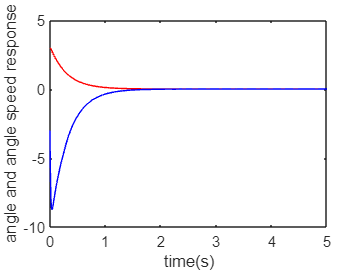

% First see and run simulink file
% sim_single_inverted_pendulum_wide_range.slx

close all;

ut = out.ut;
x = out.x;
t = out.t;

figure(1);
plot(t,x(:,1),'r',t,x(:,2),'b');
xlabel('time(s)');ylabel('angle and angle speed response');

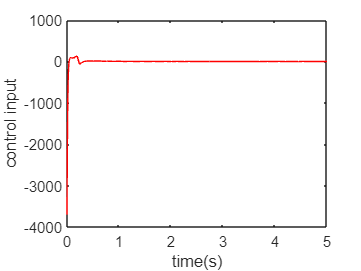


figure(2);
plot(t,ut(:,1),'r');
xlabel('time(s)');ylabel('control input');

#### 5.2.3 Find optimal value for Linear matrix inequality using YALMIP Toolbox

% Simulation example of YALMIP Toolbox
A = [-2.548 9.1 0
    1 -1 1
    0 -14.2 0];
B = [1 0 0; 0 1 0; 0 0 1];
F = sdpvar(3,3);
P = 1000000*eye(3);
FAI = (A' + F'*B')*P + P*(A+B*F);
L = [FAI <= 0];
solvesdp(L);


 Solver for LMI feasibility problems L(x) < R(x)
    This solver minimizes  t  subject to  L(x) < R(x) + t*I
    The best value of t should be negative for feasibility

 Iteration   :    Best value of t so far 
 
* switching to QR
     1                    -9.900495e+08

 Result:  best value of t: -9.900495e+08
          f-radius saturation:  99.005% of R =  1.00e+09
 
#############################################################
You are using LMILAB. Please don't use LMILAB with YALMIP
https://yalmip.github.io/solver/lmilab/
 
Install a better SDP solver
https://yalmip.github.io/allsolvers/
 
To get rid of this message, edit calllmilab.m  
(but don't expect support when things do not work,
YALMIP + LMILAB => No support)
#############################################################


F = double(F)

F =  -492.4768   -5.0500         0
   -5.0500 -494.0248    6.6000
         0    6.6000 -495.0248


## Chapter 6: Adaptive Fuzzy control

### 6.1 One Dimension function Approximation using Universal approximation theorem 

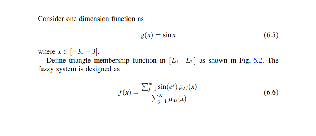

clear all;close all;

% One dimension function approximation
imshow(imread("one_dimension_function_approximation.png"));

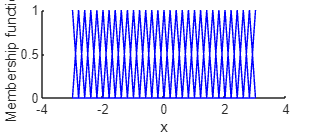


% N = 30 
L1 = -3; L2 = 3; % x is from [L1,L2]

L = L2 - L1; % Length of interval

h = 0.2; % the approximation accuracy of fuzzy system
N = L/h + 1; % number of fuzzy sets
T = 0.01; % sampling time

x = L1:T:L2;

for i = 1:N
    e(i) = L1+L/(N-1)*(i-1);
end

c=0;d=0;

clf
for j = 1:N
    if j == 1
        u = trimf(x,[e(1),e(1),e(2)]); % First MF
    elseif j == N
        u = trimf(x,[e(N-1),e(N),e(N)]); % last MF
    else
        u = trimf(x,[e(j-1) e(j) e(j+1)]);
    end
    hold on
    plot(x,u,'b');
    c = c + sin(e(j))*u;
    d = d + u;
end
xlabel('x');ylabel('Membership function');
hold off

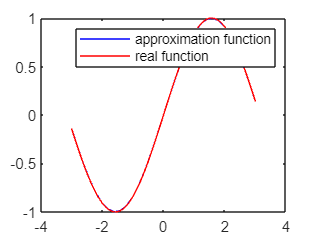


for k = 1:L/T+1
    f(k) = c(k)/d(k);
end

clf
y = sin(x);
figure(2)
plot(x,f,'b',x,y,'r');
legend('approximation function','real function');

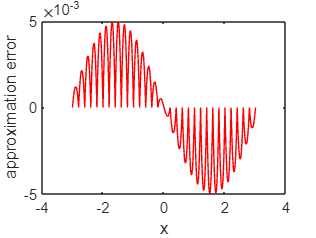


clf
figure(3)
plot(x,f-y,'r');
xlabel('x');ylabel('approximation error')

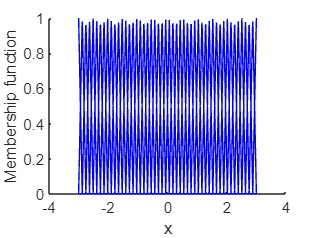


% N = 50
L1 = -3; L2 = 3; % x is from [L1,L2]

L = L2 - L1; % Length of interval

h = 0.1224; % the approximation accuracy of fuzzy system
N = 50; % number of fuzzy sets
T = 0.01; % sampling time

x = L1:T:L2;

for i = 1:N
    e(i) = L1+L/(N-1)*(i-1);
end

c=0;d=0;

clf
for j = 1:N
    if j == 1
        u = trimf(x,[e(1),e(1),e(2)]); % First MF
    elseif j == N
        u = trimf(x,[e(N-1),e(N),e(N)]); % last MF
    else
        u = trimf(x,[e(j-1) e(j) e(j+1)]);
    end
    hold on
    plot(x,u,'b');
    c = c + sin(e(j))*u;
    d = d + u;
end
xlabel('x');ylabel('Membership function');
hold off

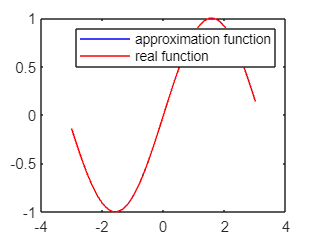


for k = 1:L/T+1
    f(k) = c(k)/d(k);
end

clf
y = sin(x);
figure(2)
plot(x,f,'b',x,y,'r');
legend('approximation function','real function');

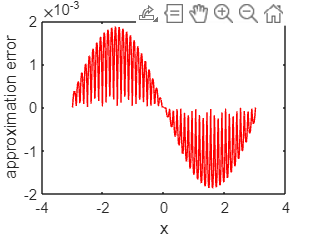


clf
figure(3)
plot(x,f-y,'r');
xlabel('x');ylabel('approximation error')

### 6.2 Two Dimension function Approximation using Universal approximation theorem

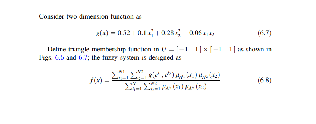

clear all;close all;

% One dimension function approximation
imshow(imread("two_dimension_function_approximation.png"));

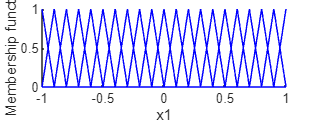


% N1 = 11 & N2 = 11

T = 0.1; % sampling time

L1 = -1; L2 = 1; % x is from [L1,L2]

L = L2 - L1; % Length of interval

x1 = L1:T:L2;
x2 = L1:T:L2;

h = 0.1; % the approximation accuracy of fuzzy system
N = L/h + 1; % number of fuzzy sets

for i = 1:N
    for j = 1:N
        e1(i) = L1+L/(N-1)*(i-1);
        e2(j) = L1+L/(N-1)*(j-1);
        gx(i,j) = 0.52 + 0.1*e1(i)^2 + 0.28*e2(j)^2 - 0.06*e1(i)*e2(j); % function to approximate
    end
end

cf=zeros(L/T+1);df=zeros(L/T + 1);

clf
for m = 1:N
    if m == 1
        u1 = trimf(x1,[e1(1),e1(1),e1(2)]); % First MF
    elseif m == N
        u1 = trimf(x1,[e1(N-1),e1(N),e1(N)]); % last MF
    else
        u1 = trimf(x1,[e1(m-1) e1(m) e1(m+1)]);
    end
    figure(1);
    hold on
    plot(x1,u1,'b');
end
xlabel('x1');ylabel('Membership function');
hold off

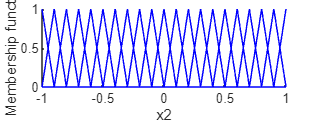


clf
for m = 1:N
    if m == 1
        u1 = trimf(x1,[e1(1),e1(1),e1(2)]); % First MF
    elseif m == N
        u1 = trimf(x1,[e1(N-1),e1(N),e1(N)]); % last MF
    else
        u1 = trimf(x1,[e1(m-1) e1(m) e1(m+1)]);
    end

for n = 1:N
    if n == 1
        u2 = trimf(x2,[e2(1),e2(1),e2(2)]); % First MF
    elseif n == N
        u2 = trimf(x2,[e2(N-1),e2(N),e2(N)]); % last MF
    else
        u2 = trimf(x2,[e2(n-1) e2(n) e2(n+1)]);
    end
    figure(2);
    hold on
    plot(x2,u2,'b');

xlabel('x2');ylabel('Membership function');
hold off

for i = 1:L/T+1
    for j = 1:L/T+1
        d = df(i,j) + u1(i)*u2(j);
        df(i,j)=d;
        c = cf(i,j) + gx(m,n)*u1(i)*u2(j);
        cf(i,j) = c;
    end
end
end
end

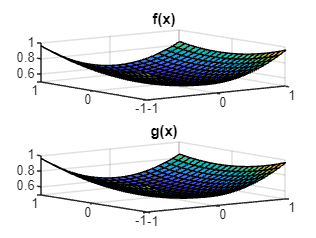


for i = 1:L/T+1
    for j = 1:L/T+1
        f(i,j) = cf(i,j)/df(i,j);
        y(i,j) = 0.52 + 0.1*x1(i)^2 + 0.28*x2(j)^2 - 0.06*x1(i)*x2(j); 
    end
end

clf
figure(3)
subplot(211);
surf(x1,x2,f);
title('f(x)');
subplot(212);
surf(x1,x2,y);
title('g(x)');

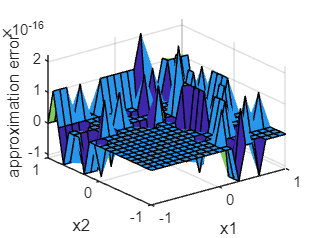


clf
figure(4)
surf(x1,x2,f-y);
xlabel('x1');ylabel('x2');zlabel('approximation error');

### 6.3 Adaptive fuzzy controller design

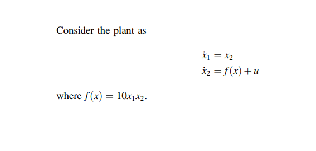

clear all;close all;

% The plant to control
imshow(imread("plant_to_control_with_adaptive_fuzzy_logic_controller.png"));

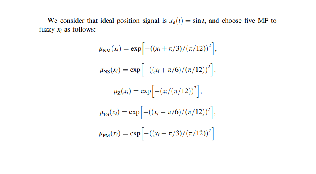


% Membership function design
imshow(imread("adaptive_fuzzy_controller_rules.png"));

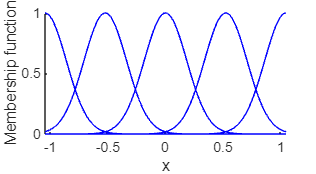


L1 = -pi/3; L2 = pi/3; % x is from [L1,L2]

L = L2 - L1; % Length of interval

T = L*1/1000; % sampling time

x = L1:T:L2;

clf

figure(1);

for i = 1:5
    gs = -[(x + pi/3 - (i-1)*pi/6) / (pi/12)].^2;
    u =exp(gs);
    hold on
    plot(x,u,'b');
end
xlabel('x');ylabel('Membership function')
hold off

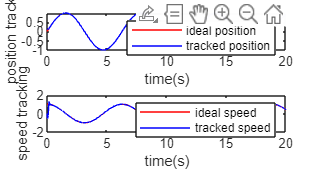

% Plot of position and speed tracking and the system function and the
% approximation of system function

clf
% To make plots first run simulink file
% Simulation_adaptive_fuzzy_logic_controller.mdl
figure(1);
subplot(211);
plot(out.t,out.x(:,1),'r',out.t,out.x(:,2),'b');
xlabel('time(s)');ylabel('position tracking');
legend('ideal position','tracked position');
subplot(212);
plot(out.t,cos(out.t),'r',out.t,out.x(:,3),'b');
xlabel('time(s)');ylabel('speed tracking');
legend('ideal speed','tracked speed');

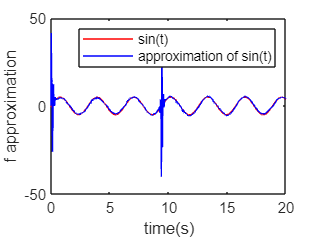


clf
figure(2);
plot(out.t,out.f(:,1),'r',out.t,out.f(:,3),'b');
xlabel('time(s)');ylabel('f approximation');
legend('sin(t)','approximation of sin(t)');

### 6.4 Adaptive fuzzy control based on fuzzy system compensator for 2 joint manipulator

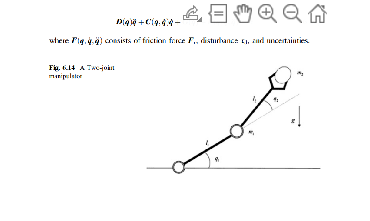

close all; 

% First, see and run simulink file Simulation_2_joint_manipulator.slx

% The plant to control
imshow(imread("2_joint_manipulator.png"));

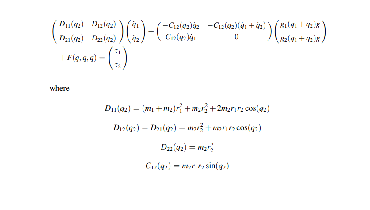

imshow(imread("2_joint_manipulator_equations.png"));

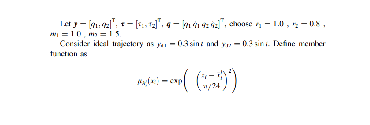

imshow(imread("2_joint_manipulator_constants.png"));

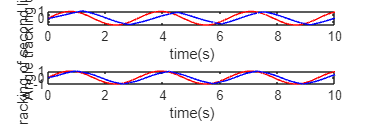


clf
figure(1);
subplot(211);
plot(out.t,out.yd1(:,1),'r',out.t,out.y(:,1),'b');
xlabel('time(s)');ylabel('Angle tracking of first link');
subplot(212);
plot(out.t,out.yd2(:,1),'r',out.t,out.y(:,3),'b');
xlabel('time(s)');ylabel('Angle tracking of second link');

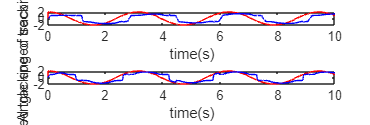


clf
figure(2);
subplot(211);
plot(out.t,out.yd1(:,2),'r',out.t,out.y(:,2),'b');
xlabel('time(s)');ylabel('Angle speed tracking of first link');
subplot(212);
plot(out.t,out.yd2(:,2),'r',out.t,out.y(:,4),'b');
xlabel('time(s)');ylabel('Angle speed tracking of second link');

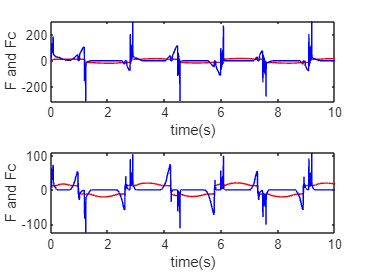


clf
figure(3);
subplot(211);
plot(out.t,out.y(:,5),'r',out.t,out.u(:,3),'b');
xlabel('time(s)');ylabel('F and Fc');
subplot(212);
plot(out.t,out.y(:,6),'r',out.t,out.u(:,4),'b');
xlabel('time(s)');ylabel('F and Fc');

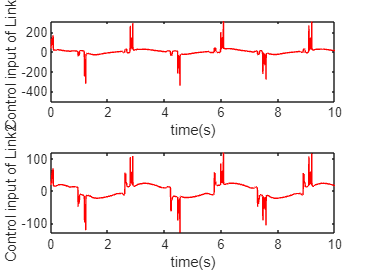


clf
figure(4);
subplot(211);
plot(out.t,out.u(:,1),'r');
xlabel('time(s)');ylabel('Control input of Link1');
subplot(212);
plot(out.t,out.u(:,2),'r');
xlabel('time(s)');ylabel('Control input of Link2');

## Chapter 7 Neural Networks

### 7.1 activation functions

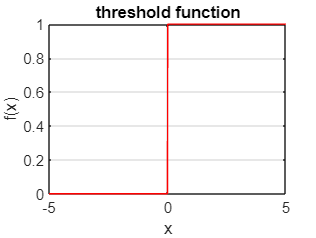

% Threshold function
t = -5:0.01:5;
f = zeros(size(t));

for i = 1:length(t)
    if t(i) > 0
        f(i) = 1;
    end
end

plot(t,f,'r');
xlabel('x');ylabel('f(x)');
title('threshold function');
grid on

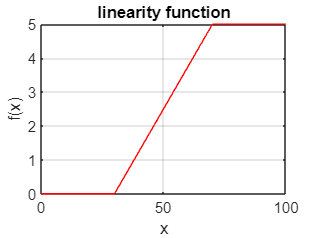


% Linearity function
t = 0:0.05:100;
f = zeros(size(t));
fmin = 0;
fmax = 5.0;
N0 = 30;
N1 = 70;
k = (fmax - fmin)/(N1 - N0);
t0 = k*N1 - 5;

for i = 1:length(t)
    if t(i) > N0 & t(i) < N1
        f(i) = k*t(i) - t0;
    elseif t(i) >= N1
        f(i) = fmax;
    end

end

plot(t,f,'r');
xlabel('x');ylabel('f(x)');
title('linearity function');
grid on

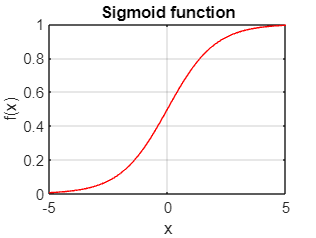


% Sigmoid function
t = -5:0.01:5;
f = zeros(size(t));
T = 1.0;

for i = 1:length(t)
    
    f(i) = 1/(1 + exp(-t(i)/T));

end

plot(t,f,'r');
xlabel('x');ylabel('f(x)');
title('Sigmoid function');
grid on

###  7.2 Backpropagation approximation of Neural Network Design and simulation

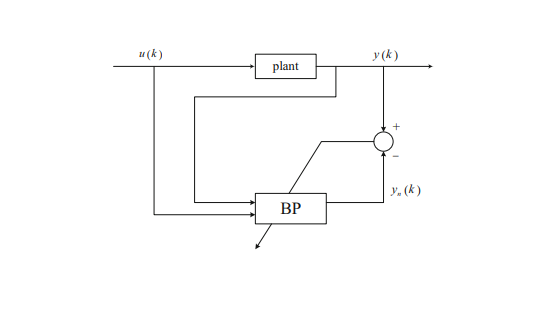

% Schema of controlling a plant using Artificial Neural Network
imshow(imread("schema_control_plant_using_ANN.png"));

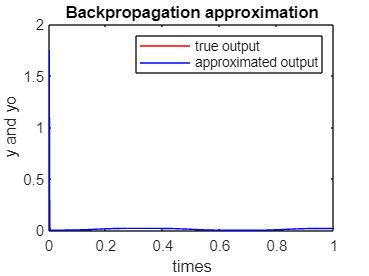


% The plant is y(k) = u(k)^3 + y(k-1)/(1 + y(k-1)^2)
% Input signal is u(k) = 0.5*sin(6pi*t);
% Input vector of neural network x = [u(k) y(k)]
% ANN structure is 2-6-1
% Activation function is sigmoid function
% Initial value of weigths of ANN is random value in [-1;1]
% Learning rate neta = 0.5
% momentum factor alpha = 0.05

clear all; close all;

xite = 0.5; % learning rate
alfa = 0.05; % momentum factor

% Initialisation of inputs and weigths of neural network

wjo = rand(6,1); % weights of output layer
wjo_1 = wjo; wjo_2 = wjo_1;

wij = rand(2,6); % weights of hidden layer
wij_1 = wij; wij_2 = wij;

dwij = 0*wij;

x = [0,0]'; % initial values of u(k) and y(k)

u_1 = 0;
y_1 = 0;

I=[0,0,0,0,0,0]'; % initialization of input of hidden layer
Iout=[0,0,0,0,0,0]'; % initialization of output of hidden layer
FI=[0,0,0,0,0,0]'; % initialization of activation function values

ts = 0.001; % sampling time

for k = 1:1000
    time(k) = k*ts;
    u(k)  = 0.05 * sin(3*pi*time(k)); % control input
    y(k) = u_1^3 + y_1/(1 + y_1^2); % output

    x(1) = u(k);
    x(2) = y(k);

    for j = 1:6
        I(j) = x'*wij(:,j); % input of hidden layer
        Iout(j) = 1 / (1 + exp(-I(j))); % Activation function and Output of hidden layer
    end

    yo(k) = wjo'*Iout; % output of Neural network

    e(k) = y(k) - yo(k); % Error calculation

    wjo = wjo_1 + (xite*e(k))*Iout + alfa*(wjo_1 - wjo_2); % new weights of output layer of ANN

    for j = 1:6
        FI(j) = exp(-I(j))/(1 + exp(-I(j)))^2; % Derivative of activation function xj'
    end

    for i = 1:2
        for j = 1:6
            dwij(i,j) = e(k)*xite*FI(j)*wjo(j)*x(i); % xite * error * dyo/dwij = xite * error * wjo * ( xj' * (1 -xj') * xi )
        end
    end

    wij = wij_1 + dwij + alfa*(wij_1 - wij_2);

    yu = 0;
    for j = 1:6
        yu = yu + wjo(j)*wij(1,j)*FI(j); % Jacobian = dy(k)/du(k)
    end
    dyu(k) = yu;

    % affectation for the after step
    wij_2 = wij_1;wij_1 = wij;
    wjo_2 = wjo_1;wjo_1 = wjo;
    u_1 = u(k);
    y_1 = y(k);
end

clf
figure(1);
plot(time,y,'r',time,yo,'b');
xlabel('times');ylabel('y and yo');
legend('true output','approximated output');
title('Backpropagation approximation');

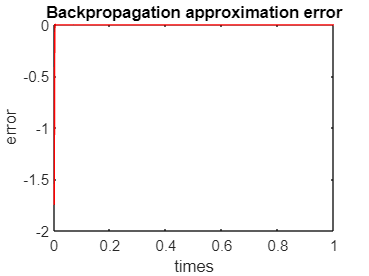



clf
figure(2);
plot(time,y-yo,'r');
xlabel('times');ylabel('error');
title('Backpropagation approximation error');

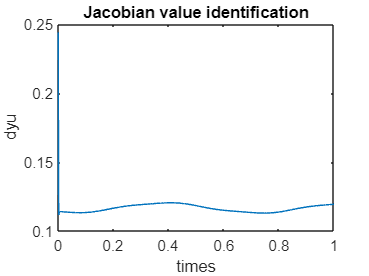


clf
figure(3);
plot(time,dyu);
xlabel('times');ylabel('dyu');
title('Jacobian value identification');

### 7.3 Radial Basis Function (RBF) Design and Simulation

#### 7.3.1  For Structure 1-5-1 RBF Neural Network

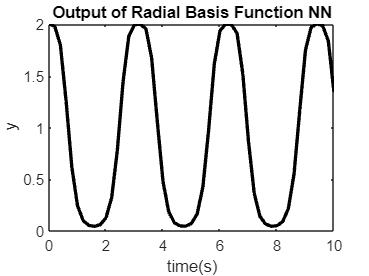

% See and run Simulink file sim_rbf.slx

% Plot radial basis function neural network response

close all;

t = out.t;
y = out.y;
% y=y(:,1);
% x=y(:,2);
% h1=y(:,3);
% h2=y(:,4);
% h3=y(:,5);
% h4=y(:,6);
% h5=y(:,7);
figure(1);
plot(t,y(:,1),'k','linewidth',2);
xlabel('time(s)');ylabel('y');
title('Output of Radial Basis Function NN')

figure(2);
plot(y(:,2),y(:,3),'k','linewidth',2);
xlabel('x');ylabel('hj');
hold on;
plot(y(:,2),y(:,4),'k','linewidth',2);
hold on;
plot(y(:,2),y(:,5),'k','linewidth',2);
hold on;
plot(y(:,2),y(:,6),'k','linewidth',2);
hold on;
plot(y(:,2),y(:,7),'k','linewidth',2);
title('Output of hidden RBF NN')


#### 7.3.2  For Structure 2-5-1 RBF Neural Network

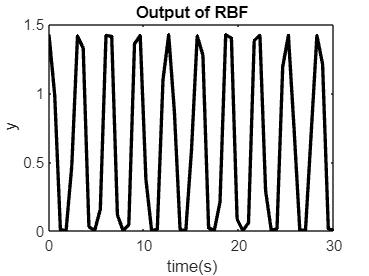

% See and run Simulink file sim_rbf2.slx

% Plot radial basis function neural network response for structure 2-5-1

t = out.t;
y = out.y;

close all;
% y=y(:,1);
% x1=y(:,2);
% x2=y(:,3);
% h1=y(:,4);
% h2=y(:,5);
% h3=y(:,6);
% h4=y(:,7);
% h5=y(:,8);
figure(1);
plot(t,y(:,1),'k','linewidth',2);
xlabel('time(s)');ylabel('y');
title('Output of RBF');

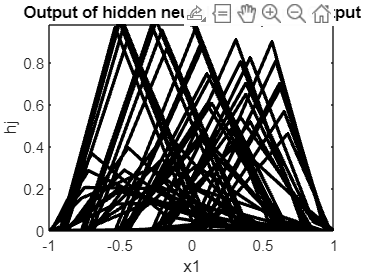


% Plot gaussian function output of hidden neural network for 2 inputs
clf;
figure(2);
plot(y(:,2),y(:,4),'k','linewidth',2);
xlabel('x1');ylabel('hj');
hold on;
plot(y(:,2),y(:,5),'k','linewidth',2);
hold on;
plot(y(:,2),y(:,6),'k','linewidth',2);
hold on;
plot(y(:,2),y(:,7),'k','linewidth',2);
hold on;
plot(y(:,2),y(:,8),'k','linewidth',2);
title('Output of hidden neural net for first Output');

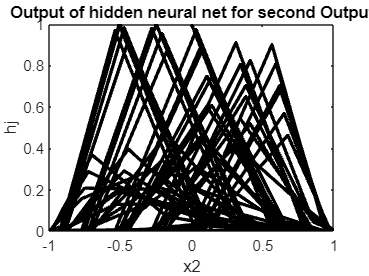


clf;
figure(3);
plot(y(:,3),y(:,4),'k','linewidth',2);
xlabel('x2');ylabel('hj');
hold on;
plot(y(:,3),y(:,5),'k','linewidth',2);
hold on;
plot(y(:,3),y(:,6),'k','linewidth',2);
hold on;
plot(y(:,3),y(:,7),'k','linewidth',2);
hold on;
plot(y(:,3),y(:,8),'k','linewidth',2);
title('Output of hidden neural net for second Output');

### 7.4 RBF Neural Network Approximation based on Gradient Descent Method

#### 7.4.1 RBF Neural Network Approximation - Example 1

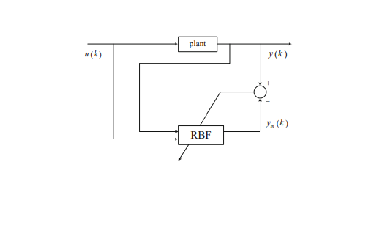

% Schema of controlling a plant using Artificial Neural Network
close all;
imshow(imread("RBF_NN_approximation.png"));

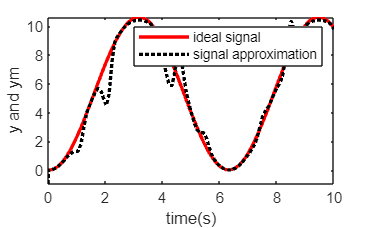


% The plant is G(s) = 133 / (s^2 + 25s);
% Input signal is u(k) = sin(t);
% Input vector of neural network x = [u(k) y(k)]
% ANN structure is 2-5-1
% Activation function is gaussian function
% Initial value of weigths of ANN is random value in [-1;1]
% Learning rate xite = 0.5
% momentum factor alpha = 0.05

% see and run simulink file sim_rbf3.slk

t = out.t;
y = out.y;

figure(1);
plot(t,y(:,1),'r' ,'linewidth',2);
hold on
plot(t,y(:,2),'k:','linewidth',2);
xlabel('time(s)');ylabel('y and ym');
legend('ideal signal','signal approximation');

#### 7.4.2 RBF Neural Network Approximation - Example 2

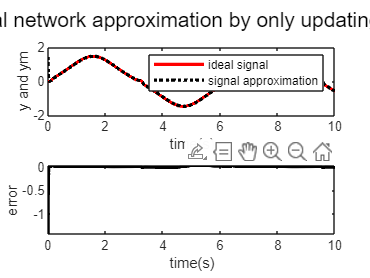

% The plant is described by the following example
% y(k) = u(k)^3 + y(k-1)/(1 + y(k-1)^2)
% Input signal is u(k) = sin(t);
% Input vector of neural network x = [u(k) y(k)]
% ANN structure is 2-5-1
% Activation function is gaussian function
% Initial value of weigths of ANN is random value in [-1;1]
% Learning rate xite = 0.15
% momentum factor alpha = 0.05
% Only update weights

%RBF approximation
clear all;
close all;
alfa=0.05;
xite=0.15;
x=[0,1]';

b=3*ones(5,1);
c=[-1 -0.5 0 0.5 1;
   -1 -0.5 0 0.5 1];

w=rands(5,1);
w_1=w;w_2=w_1;
c_1=c;c_2=c_1;
b_1=b;b_2=b_1;
d_w=0*w;
d_b=0*b;
y_1=0;
ts=0.001;

for k=1:10000
    time(k)=k*ts;
    u(k)=sin(k*ts);
    y(k)=u(k)^3+y_1/(1+y_1^2);
    x(1)=u(k);
    x(2)=y_1;
    for j=1:1:5
        h(j)=exp(-norm(x-c(:,j))^2/(2*b(j)*b(j)));
    end
    ym(k)=w'*h';
    em(k)=y(k)-ym(k);
    M=1;
    if M==1 %Only weight value update
        d_w(j)=xite*em(k)*h(j);
    elseif M==2 %Update w,b,c
        for j=1:5
            d_w(j)=xite*em(k)*h(j);
            d_b(j)=xite*em(k)*w(j)*h(j)*(b(j)^-3)*norm(x-c(:,j))^2;
            for i=1:1:2
                d_c(i,j)=xite*em(k)*w(j)*h(j)*(x(i)-c(i,j))*(b(j)^-2);
            end
        end
        b=b_1+d_b+alfa*(b_1-b_2);
        c=c_1+d_c+alfa*(c_1-c_2);
    end
    w=w_1+d_w+alfa*(w_1-w_2);
    y_1=y(k);
    
    w_2=w_1;
    w_1=w;
    c_2=c_1;
    c_1=c;
    b_2=b_1;
    b_1=b;
end

figure(1);

subplot(211);
plot(time,y,'r',time,ym,'k:','linewidth',2);
xlabel('time(s)');ylabel('y and ym');
legend('ideal signal','signal approximation');
subplot(212);
plot(time,y-ym,'k','linewidth',2);
xlabel('time(s)');ylabel('error');
sgtitle(' RBF neural network approximation by only updating w (M = 1)');

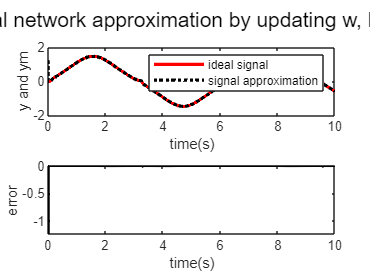

% The plant is described by the following example
% y(k) = u(k)^3 + y(k-1)/(1 + y(k-1)^2)
% Input signal is u(k) = sin(t);
% Input vector of neural network x = [u(k) y(k)]
% ANN structure is 2-5-1
% Activation function is gaussian function
% Initial value of weigths of ANN is random value in [-1;1]
% Learning rate xite = 0.15
% momentum factor alpha = 0.05
% update weights, b and c

%RBF approximation
clear all;
close all;
alfa=0.05;
xite=0.15;
x=[0,1]';

b=3*ones(5,1);
c=[-1 -0.5 0 0.5 1;
   -1 -0.5 0 0.5 1];

w=rands(5,1);
w_1=w;w_2=w_1;
c_1=c;c_2=c_1;
b_1=b;b_2=b_1;
d_w=0*w;
d_b=0*b;
y_1=0;
ts=0.001;

for k=1:10000
    time(k)=k*ts;
    u(k)=sin(k*ts);
    y(k)=u(k)^3+y_1/(1+y_1^2);
    x(1)=u(k);
    x(2)=y_1;
    for j=1:1:5
        h(j)=exp(-norm(x-c(:,j))^2/(2*b(j)*b(j)));
    end
    ym(k)=w'*h';
    em(k)=y(k)-ym(k);
    M=2;
    if M==1 %Only weight value update
        d_w(j)=xite*em(k)*h(j);
    elseif M==2 %Update w,b,c
        for j=1:5
            d_w(j)=xite*em(k)*h(j);
            d_b(j)=xite*em(k)*w(j)*h(j)*(b(j)^-3)*norm(x-c(:,j))^2;
            for i=1:1:2
                d_c(i,j)=xite*em(k)*w(j)*h(j)*(x(i)-c(i,j))*(b(j)^-2);
            end
        end
        b=b_1+d_b+alfa*(b_1-b_2);
        c=c_1+d_c+alfa*(c_1-c_2);
    end
    w=w_1+d_w+alfa*(w_1-w_2);
    y_1=y(k);
    
    w_2=w_1;
    w_1=w;
    c_2=c_1;
    c_1=c;
    b_2=b_1;
    b_1=b;
end

figure(1);
subplot(211);
plot(time,y,'r',time,ym,'k:','linewidth',2);
xlabel('time(s)');ylabel('y and ym');
legend('ideal signal','signal approximation');
subplot(212);
plot(time,y-ym,'k','linewidth',2);
xlabel('time(s)');ylabel('error');
sgtitle(' RBF neural network approximation by updating w, b, c (M = 2)')

### 7.5 Effects of Analysis on RBF Approximation

% We approximate the following discrete plant 
% y(k) = u(k)^3 + y(k-1)/(1 + y(k-1)^2)

#### 7.5.1 Effects of Gaussian Function Parameters on RBF Approximation

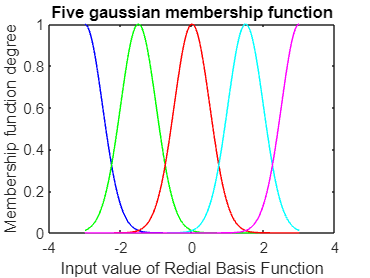

% For the simulations in this chapter we choose
% alpha = 0.05 and xite = 0.5
% The initial weight values are zeros
% We will analyze the effect of center vector cj and width value bj
% Design of five gaussian membership function

%RBF function
clear all;
close all;
c=[-3 -1.5 0 1.5 3];

M=1;
if M==1
    b=0.50*ones(5,1);
elseif M==2
    b=1.50*ones(5,1);
end

h=[0,0,0,0,0]';
ts=0.001;
for k=1:1:2000
    time(k)=k*ts;
    %RBF function
    x(1)=3*sin(2*pi*k*ts);
    for j=1:1:5
        h(j)=exp(-norm(x-c(:,j))^2/(2*b(j)*b(j)));
    end
    x1(k)=x(1);
    %First Redial Basis Function
    h1(k)=h(1);
    %Second Redial Basis Function
    h2(k)=h(2);
    %Third Redial Basis Function
    h3(k)=h(3);
    %Fourth Redial Basis Function
    h4(k)=h(4);
    %Fifth Redial Basis Function
    h5(k)=h(5);
end

figure(1);
plot(x1,h1,'b');
hold on;
plot(x1,h2,'g');
hold on;
plot(x1,h3,'r');
hold on;
plot(x1,h4,'c');
hold on;
plot(x1,h5,'m');
xlabel('Input value of Redial Basis Function');
ylabel('Membership function degree');
title('Five gaussian membership function')

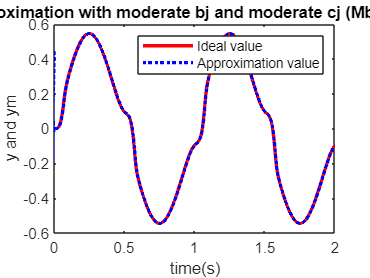

% alpha = 0.05 and xite = 0.5
% The initial weight values are zeros
% We will analyze the effect of center vector cj and width value bj and
% number of hidden nets
% See the effect of cj and bj on the RBF approximation

% RBF approximation with moderate bj and moderate cj (Mb = 1, Mc = 1)

%RBF approximation test
clear all;
close all;
alfa=0.05;
xite=0.5;

x=[0,0]';
%The parameters design of Guassian Function
%The input of RBF (u(k),y(k)) must be in the effect range of Guassian function overlay
%The value of b represents the widenth of Guassian function overlay
Mb=1;
if Mb==1 %The width of Guassian function is moderate
    b=1.5*ones(5,1);
elseif Mb==2 %The width of Guassian function is too narrow, most overlap of the function is near to zero
    b=0.0005*ones(5,1);
end
%The value of c represents the center position of Guassian function overlay
%the NN structure is 2-5-1: i=2; j=1,2,3,4,5; k=1
Mc=1;
if Mc==1 %The center position of Guassian function is moderate
    c=[-1.5 -0.5 0 0.5 1.5;
       -1.5 -0.5 0 0.5 1.5]; %cij
elseif Mc==2 %The center position of Guassian function is improper
    c=0.1*[-1.5 -0.5 0 0.5 1.5;
           -1.5 -0.5 0 0.5 1.5]; %cij
end

w=rands(5,1);
w_1=w;w_2=w_1;
y_1=0;
ts=0.001;

for k=1:1:2000
    time(k)=k*ts;
    u(k)=0.50*sin(1*2*pi*k*ts);
    y(k)=u(k)^3+y_1/(1+y_1^2);
    x(1)=u(k);
    x(2)=y(k);
    for j=1:1:5
        h(j)=exp(-norm(x-c(:,j))^2/(2*b(j)*b(j)));
    end
    ym(k)=w'*h';
    em(k)=y(k)-ym(k);
    d_w=xite*em(k)*h';
    w=w_1+ d_w+alfa*(w_1-w_2);
    
    y_1=y(k);
    w_2=w_1;w_1=w;
end

figure(1);
plot(time,y,'r',time,ym,'b:','linewidth',2);
xlabel('time(s)');ylabel('y and ym');
legend('Ideal value','Approximation value');
title('RBF approximation with moderate bj and moderate cj (Mb = 1, Mc = 1)')

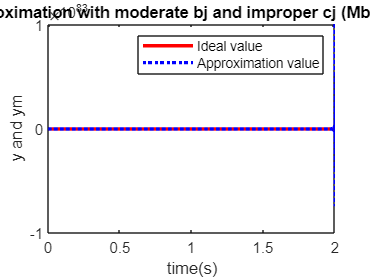

% RBF approximation with moderate bj and improper cj (Mb = 1, Mc = 2)

%RBF approximation test
clear all;
close all;
alfa=0.05;
xite=0.5;

x=[0,0]';
%The parameters design of Guassian Function
%The input of RBF (u(k),y(k)) must be in the effect range of Guassian function overlay
%The value of b represents the widenth of Guassian function overlay
Mb=1;
if Mb==1 %The width of Guassian function is moderate
    b=1.5*ones(5,1);
elseif Mb==2 %The width of Guassian function is too narrow, most overlap of the function is near to zero
    b=0.0005*ones(5,1);
end
%The value of c represents the center position of Guassian function overlay
%the NN structure is 2-5-1: i=2; j=1,2,3,4,5; k=1
Mc=2;
if Mc==1 %The center position of Guassian function is moderate
    c=[-1.5 -0.5 0 0.5 1.5;
       -1.5 -0.5 0 0.5 1.5]; %cij
elseif Mc==2 %The center position of Guassian function is improper
    c=0.1*[-1.5 -0.5 0 0.5 1.5;
           -1.5 -0.5 0 0.5 1.5]; %cij
end

w=rands(5,1);
w_1=w;w_2=w_1;
y_1=0;
ts=0.001;

for k=1:1:2000
    time(k)=k*ts;
    u(k)=0.50*sin(1*2*pi*k*ts);
    y(k)=u(k)^3+y_1/(1+y_1^2);
    x(1)=u(k);
    x(2)=y(k);
    for j=1:1:5
        h(j)=exp(-norm(x-c(:,j))^2/(2*b(j)*b(j)));
    end
    ym(k)=w'*h';
    em(k)=y(k)-ym(k);
    d_w=xite*em(k)*h';
    w=w_1+ d_w+alfa*(w_1-w_2);
    
    y_1=y(k);
    w_2=w_1;w_1=w;
end

figure(1);
plot(time,y,'r',time,ym,'b:','linewidth',2);
xlabel('time(s)');ylabel('y and ym');
legend('Ideal value','Approximation value');
title('RBF approximation with moderate bj and improper cj (Mb = 1, Mc = 2)')

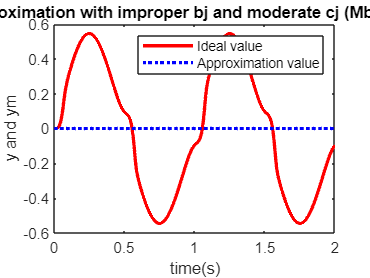

% RBF approximation with improper bj and moderate cj (Mb = 2, Mc = 1)

%RBF approximation test
clear all;
close all;
alfa=0.05;
xite=0.5;

x=[0,0]';
%The parameters design of Guassian Function
%The input of RBF (u(k),y(k)) must be in the effect range of Guassian function overlay
%The value of b represents the widenth of Guassian function overlay
Mb=2;
if Mb==1 %The width of Guassian function is moderate
    b=1.5*ones(5,1);
elseif Mb==2 %The width of Guassian function is too narrow, most overlap of the function is near to zero
    b=0.0005*ones(5,1);
end
%The value of c represents the center position of Guassian function overlay
%the NN structure is 2-5-1: i=2; j=1,2,3,4,5; k=1
Mc=1;
if Mc==1 %The center position of Guassian function is moderate
    c=[-1.5 -0.5 0 0.5 1.5;
       -1.5 -0.5 0 0.5 1.5]; %cij
elseif Mc==2 %The center position of Guassian function is improper
    c=0.1*[-1.5 -0.5 0 0.5 1.5;
           -1.5 -0.5 0 0.5 1.5]; %cij
end

w=rands(5,1);
w_1=w;w_2=w_1;
y_1=0;
ts=0.001;

for k=1:1:2000
    time(k)=k*ts;
    u(k)=0.50*sin(1*2*pi*k*ts);
    y(k)=u(k)^3+y_1/(1+y_1^2);
    x(1)=u(k);
    x(2)=y(k);
    for j=1:1:5
        h(j)=exp(-norm(x-c(:,j))^2/(2*b(j)*b(j)));
    end
    ym(k)=w'*h';
    em(k)=y(k)-ym(k);
    d_w=xite*em(k)*h';
    w=w_1+ d_w+alfa*(w_1-w_2);
    
    y_1=y(k);
    w_2=w_1;w_1=w;
end

figure(1);
plot(time,y,'r',time,ym,'b:','linewidth',2);
xlabel('time(s)');ylabel('y and ym');
legend('Ideal value','Approximation value');
title('RBF approximation with improper bj and moderate cj (Mb = 2, Mc = 1)')

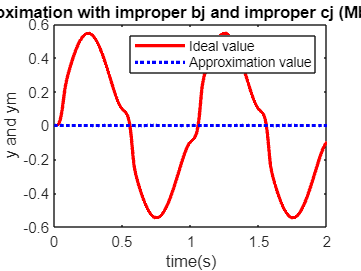

% RBF approximation with improper bj and improper cj (Mb = 2, Mc = 2)

%RBF approximation test
clear all;
close all;
alfa=0.05;
xite=0.5;

x=[0,0]';
%The parameters design of Guassian Function
%The input of RBF (u(k),y(k)) must be in the effect range of Guassian function overlay
%The value of b represents the widenth of Guassian function overlay
Mb=2;
if Mb==1 %The width of Guassian function is moderate
    b=1.5*ones(5,1);
elseif Mb==2 %The width of Guassian function is too narrow, most overlap of the function is near to zero
    b=0.0005*ones(5,1);
end
%The value of c represents the center position of Guassian function overlay
%the NN structure is 2-5-1: i=2; j=1,2,3,4,5; k=1
Mc=2;
if Mc==1 %The center position of Guassian function is moderate
    c=[-1.5 -0.5 0 0.5 1.5;
       -1.5 -0.5 0 0.5 1.5]; %cij
elseif Mc==2 %The center position of Guassian function is improper
    c=0.1*[-1.5 -0.5 0 0.5 1.5;
           -1.5 -0.5 0 0.5 1.5]; %cij
end

w=rands(5,1);
w_1=w;w_2=w_1;
y_1=0;
ts=0.001;

for k=1:1:2000
    time(k)=k*ts;
    u(k)=0.50*sin(1*2*pi*k*ts);
    y(k)=u(k)^3+y_1/(1+y_1^2);
    x(1)=u(k);
    x(2)=y(k);
    for j=1:1:5
        h(j)=exp(-norm(x-c(:,j))^2/(2*b(j)*b(j)));
    end
    ym(k)=w'*h';
    em(k)=y(k)-ym(k);
    d_w=xite*em(k)*h';
    w=w_1+ d_w+alfa*(w_1-w_2);
    
    y_1=y(k);
    w_2=w_1;w_1=w;
end

figure(1);
plot(time,y,'r',time,ym,'b:','linewidth',2);
xlabel('time(s)');ylabel('y and ym');
legend('Ideal value','Approximation value');
title('RBF approximation with improper bj and improper cj (Mb = 2, Mc = 2)')

#### 7.5.2 Effects of Hidden Nets Number on RBF Approximation

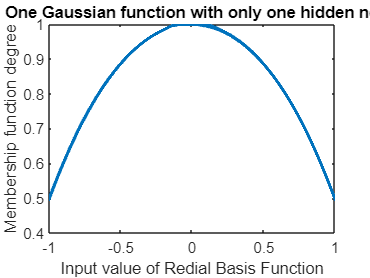

% alpha = 0.05 and xite = 0.3
% The initial weight values are zeros
% bj = 1.5
% u(k) = sin(t)
% The structure of NN is 2-m-1
% m is the number of hidden nets
% We will analyze the effect of number of hidden nets on RBF approximation

% for m = 1 we choose cj = 0;

%RBF approximation test
clear all;
close all;

alfa=0.05;
xite=0.3;
x=[0,0]';

%The parameters design of Guassian Function
%The input of RBF (u(k),y(k))must be in the effect range of Guassian func�tion overlay
%The value of b represents the widenth of Guassian function overlay

bj=1.5; %The width of Guassian function
%The value of c represents the center position of Guassian function overlay
%the NN structure is 2-m-1: i=2; j=1,2,…,m; k=1
M=1; %Different hidden nets number
if M==1 %only one hidden net
    m=1;
    c=0;
elseif M==2
    m=3;
    c=1/3*[-1 0 1;
           -1 0 1];
elseif M==3
    m=7;
    c=1/9*[-3 -2 -1 0 1 2 3;
           -3 -2 -1 0 1 2 3];
end

w=zeros(m,1);
w_1=w;w_2=w_1;
y_1=0;
ts=0.001;

for k=1:1:5000
    time(k)=k*ts;
    u(k)=sin(k*ts);
    y(k)=u(k)^3+y_1/(1+y_1^2);
    x(1)=u(k);
    x(2)=y(k);

    for j=1:1:m
        h(j)=exp(-norm(x-c(:,j))^2/(2*bj^2));
    end

    ym(k)=w'*h';
    em(k)=y(k)-ym(k);
    d_w=xite*em(k)*h';
    w=w_1+ d_w+alfa*(w_1-w_2);
    y_1=y(k);
    w_2=w_1;w_1=w;
    x1(k)=x(1);

    for j=1:1:m
        H(j,k)=h(j);
    end

    if k==5000
        figure(1);
        for j=1:1:m
            plot(x1,H(j,:),'linewidth',2);
            hold on;
        end
        xlabel('Input value of Redial Basis Function');
        ylabel('Membership function degree');
        title(' One Gaussian function with only one hidden net')
    end
end

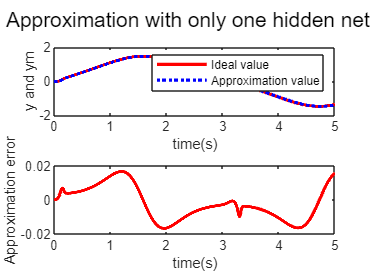


figure(2);
subplot(211);
plot(time,y,'r',time,ym,'b:','linewidth',2);
xlabel('time(s)');ylabel('y and ym');
legend('Ideal value','Approximation value');
subplot(212);
plot(time,y-ym,'r','linewidth',2);
xlabel('time(s)');ylabel('Approximation error');
sgtitle(' Approximation with only one hidden net')

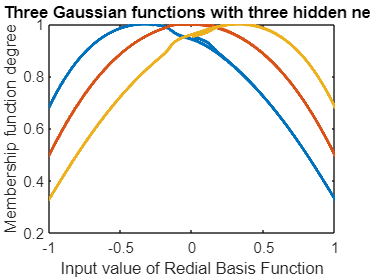

% for m = 3 we choose cj = 1/3 * [-1 0 1; -1 0 1]';

%RBF approximation test
clear all;
close all;

alfa=0.05;
xite=0.3;
x=[0,0]';

%The parameters design of Guassian Function
%The input of RBF (u(k),y(k))must be in the effect range of Guassian func�tion overlay
%The value of b represents the widenth of Guassian function overlay

bj=1.5; %The width of Guassian function
%The value of c represents the center position of Guassian function overlay
%the NN structure is 2-m-1: i=2; j=1,2,…,m; k=1
M=2; %Different hidden nets number
if M==1 %only one hidden net
    m=1;
    c=0;
elseif M==2 % Three hidden nets
    m=3;
    c=1/3*[-1 0 1;
           -1 0 1];
elseif M==3
    m=7;
    c=1/9*[-3 -2 -1 0 1 2 3;
           -3 -2 -1 0 1 2 3];
end

w=zeros(m,1);
w_1=w;w_2=w_1;
y_1=0;
ts=0.001;

for k=1:1:5000
    time(k)=k*ts;
    u(k)=sin(k*ts);
    y(k)=u(k)^3+y_1/(1+y_1^2);
    x(1)=u(k);
    x(2)=y(k);

    for j=1:1:m
        h(j)=exp(-norm(x-c(:,j))^2/(2*bj^2));
    end

    ym(k)=w'*h';
    em(k)=y(k)-ym(k);
    d_w=xite*em(k)*h';
    w=w_1+ d_w+alfa*(w_1-w_2);
    y_1=y(k);
    w_2=w_1;w_1=w;
    x1(k)=x(1);

    for j=1:1:m
        H(j,k)=h(j);
    end

    if k==5000
        figure(1);
        for j=1:1:m
            plot(x1,H(j,:),'linewidth',2);
            hold on;
        end
        xlabel('Input value of Redial Basis Function');
        ylabel('Membership function degree');
        title(' Three Gaussian functions with three hidden nets')
    end
end

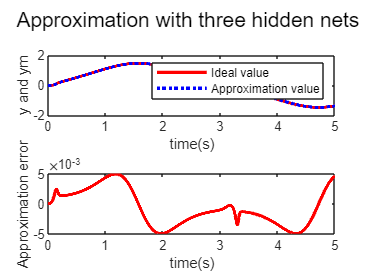


figure(2);
subplot(211);
plot(time,y,'r',time,ym,'b:','linewidth',2);
xlabel('time(s)');ylabel('y and ym');
legend('Ideal value','Approximation value');
subplot(212);
plot(time,y-ym,'r','linewidth',2);
xlabel('time(s)');ylabel('Approximation error');
sgtitle(' Approximation with three hidden nets')

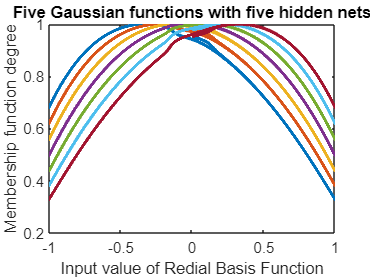

% for m = 7 we choose cj = 1/9 * [-3 -2 -1 0 1 2 3;-3 -2 -1 0 1 2 3]';

%RBF approximation test
clear all;
close all;

alfa=0.05;
xite=0.3;
x=[0,0]';

%The parameters design of Guassian Function
%The input of RBF (u(k),y(k))must be in the effect range of Guassian function overlay
%The value of b represents the widenth of Guassian function overlay

bj=1.5; %The width of Guassian function
%The value of c represents the center position of Guassian function overlay
%the NN structure is 2-m-1: i=2; j=1,2,…,m; k=1
M=3; %Different hidden nets number
if M==1 %only one hidden net
    m=1;
    c=0;
elseif M==2 % Three hidden nets
    m=3;
    c=1/3*[-1 0 1;
           -1 0 1];
elseif M==3
    m=7;
    c=1/9*[-3 -2 -1 0 1 2 3;
           -3 -2 -1 0 1 2 3];
end

w=zeros(m,1);
w_1=w;w_2=w_1;
y_1=0;
ts=0.001;

for k=1:1:5000
    time(k)=k*ts;
    u(k)=sin(k*ts);
    y(k)=u(k)^3+y_1/(1+y_1^2);
    x(1)=u(k);
    x(2)=y(k);

    for j=1:1:m
        h(j)=exp(-norm(x-c(:,j))^2/(2*bj^2));
    end

    ym(k)=w'*h';
    em(k)=y(k)-ym(k);
    d_w=xite*em(k)*h';
    w=w_1+ d_w+alfa*(w_1-w_2);
    y_1=y(k);
    w_2=w_1;w_1=w;
    x1(k)=x(1);

    for j=1:1:m
        H(j,k)=h(j);
    end

    if k==5000
        figure(1);
        for j=1:1:m
            plot(x1,H(j,:),'linewidth',2);
            hold on;
        end
        xlabel('Input value of Redial Basis Function');
        ylabel('Membership function degree');
        title('Five Gaussian functions with five hidden nets')
    end
end

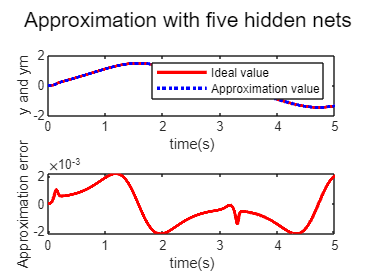


figure(2);
subplot(211);
plot(time,y,'r',time,ym,'b:','linewidth',2);
xlabel('time(s)');ylabel('y and ym');
legend('Ideal value','Approximation value');
subplot(212);
plot(time,y-ym,'r','linewidth',2);
xlabel('time(s)');ylabel('Approximation error');
sgtitle(' Approximation with five hidden nets')

### 7.6 RBF Neural Network Training for System Modeling

#### 7.6.1 RBF Neural Network Training

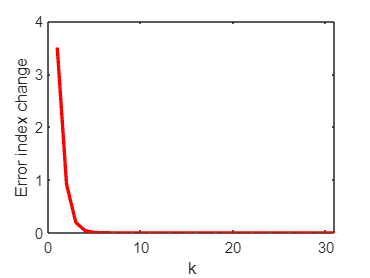

% First example Multi-input Multi-Output (MIMO)
% We choose 3 inputs and 2 outputs
% The structure of RBF network is 3-5-2
% cj = [-1 -0.5 0 0.5 1;-1 -0.5 0 0.5 1;-1 -0.5 0 0.5 1]
% bj = 10
% The initial weights are choosen randomly from [-1;1]
% momentum factor xite = 0.1 and learning rate alpha = 0.05

%RBF Training for MIMO

clear all;
close all;

xite=0.10;
alfa=0.05;

W=rands(5,2);
W_1=W;
W_2=W_1;

h=[0,0,0,0,0]';
c=2*[-0.5 -0.25 0 0.25 0.5;
-0.5 -0.25 0 0.25 0.5;
-0.5 -0.25 0 0.25 0.5]; %cij
b=10; %bj

xs=[1,0,0];%Ideal Input
ys=[1,0]; %Ideal Output

OUT=2;
NS=1;
k=0;
E=1.0;
while E>=1e-020
    %for k=1:1:1000
    k=k+1;
    times(k)=k;
    for s=1:1:NS %MIMO Samples
        x=xs(s,:);
        for j=1:1:5
            h(j)=exp(-norm(x'-c(:,j))^2/(2*b^2)); %Hidden Layer
        end
        yl=W'*h; %Output Layer
        el=0;
        y=ys(s,:);
        for l=1:1:OUT
            el=el+0.5*(y(l)-yl(l))^2; %Output error
        end
        es(s)=el;
        E=0;
        if s==NS
            for s=1:1:NS
                E=E+es(s);
            end
        end
        error=y-yl';
        dW=xite*h*error;
        W=W_1+dW+alfa*(W_1-W_2);
        W_2=W_1;W_1=W;
    end %End of for
    Ek(k)=E;
end %End of while

figure(1);
plot(times,Ek,'r','linewidth',2);
xlabel('k');ylabel('Error index change');


save wfile b c W;

%Test MIMO RBF
clear all;

load wfile b c W;

%N Samples
x=[0.970,0.001,0.001;
   1.000,0.000,0.000];

NS=2;
h=zeros(5,1); %hj
for i=1:1:NS
    for j=1:1:5
        h(j)=exp(-norm(x(i,:)'-c(:,j))^2/(2*b^2)); %Hidden Layer
    end
    yl(i,:)=W'*h; %Output Layer
end
yl

yl =     1.0001   -0.0002
    1.0000    0.0000


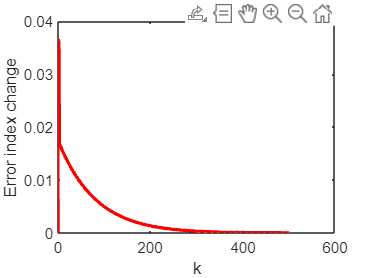

% Second example System modeling with RBF
% y(k) = 0.5*[y(k-1)*(1-y(k-1))]/[1 + exp(-0.25y(k-1))] + u(k-1)
% The structure of RBF network is 2-5-1
% Inputs are u(k) and y(k)
% cj = [-3 -2 -1 0 1 2 3;-3 -2 -1 0 1 2 3;-3 -2 -1 0 1 2 3]
% bj = 1.5
% The initial weights are choosen 0.1
% momentum factor xite = 0.5 and learning rate alpha = 0.05
% u(k) = sin(t) with t = k*ts and ts = 0.001 (sampling time)
% the number of sample is NS = 3000

% System training
%RBF Training for a Plant
clear all;
close all;

ts=0.001;
xite=0.50;
alfa=0.05;
u_1=0;y_1=0;
fx_1=0;
W=0.1*ones(1,7);
W_1=W;
W_2=W_1;
h=zeros(7,1);
c1=[-3 -2 -1 0 1 2 3];
c2=[-3 -2 -1 0 1 2 3];
c=[c1;c2];
b=1.5; %bj
NS=3000;

for s=1:1:NS %Samples
    u(s)=sin(s*ts);
    fx(s)=0.5*y_1*(1-y_1)/(1+exp(-0.25*y_1));
    y(s)=fx_1+u_1;
    u_1=u(s);
    y_1=y(s);
    fx_1=fx(s);
end

k=0;
for k=1:1:500
    k=k+1;
    times(k)=k;
    for s=1:1:NS %Samples
        x=[u(s),y(s)];
        for j=1:1:7
            h(j)=exp(-norm(x'-c(:,j))^2/(2*b^2)); %Hidden Layer
        end
        yl(s)=W*h; %Output Layer
        el=0.5*(y(s)-yl(s))^2; %Output error
        es(s)=el;
        E=0;
        if s==NS
            for s=1:1:NS
                E=E+es(s);
            end
        end
        error=y(s)-yl(s);
        dW=xite*h'*error;
        W=W_1+dW+alfa*(W_1-W_2);
        W_2=W_1;W_1=W;
    end %End of for
    Ek(k)=E;
end %End of while

figure(1);
plot(times,Ek,'r','linewidth',2);
xlabel('k');ylabel('Error index change');

save wfile2 b c W NS;

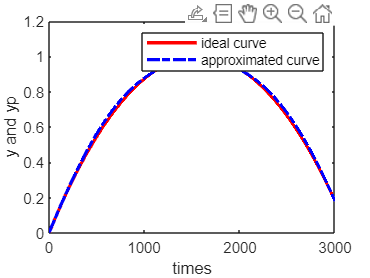

% System test

%Online RBF Estimation for Plant
clear all;
load wfile2 b c W NS;
ts=0.001;
u_1=0;y_1=0;
fx_1=0;
h=zeros(7,1);

for k=1:1:NS
    times(k)=k;
    u(k)=sin(k*ts);
    fx(k)=0.5*y_1*(1-y_1)/(1+exp(-0.25*y_1));
    y(k)=fx_1+u_1;
    x=[u(k),y(k)];
    for j=1:1:7
        h(j)=exp(-norm(x'-c(:,j))^2/(2*b^2)); %Hidden Layer
    end
    yp(k)=W*h; %Output Layer
    u_1=u(k);y_1=y(k);
    fx_1=fx(k);
end

figure(1);
plot(times,y,'r',times,yp,'b-.','linewidth',2);
xlabel('times');ylabel('y and yp');
legend('ideal curve','approximated curve')

## Chapter 8: Adaptive RBF Neural Network Control

### 8.1  Adaptive Control based on Neural Approximation

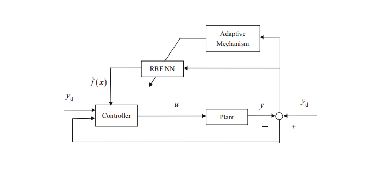

% Block diagram of the control scheme
imshow(imread("Adaptive_RBF_neural_network_approximation.png"));

#### 8.1.1 First example Linear system

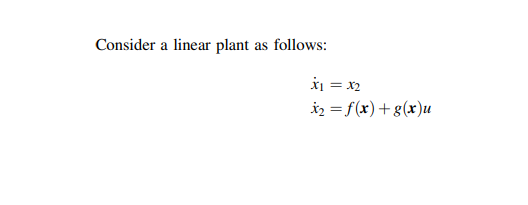

% The plant is considered bellow
imshow(imread("Adaptive_RBF_neural_network_approximation_linear_system.png"));

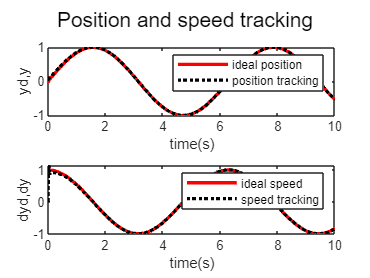


% f(x) = -25*x2 and g(x) = 133
% the ideal position signal yd(t) = sin(t)
% the initial states of the plant [pi/60,0]
% RBF network structure is 2-5-1
% cj = [-1 -0.5 0 0.5 1;-1 -0.5 0 0.5 1] and bj = 1.0
% The initial value is chosen as zero

% Q = [500 0;0 500]; kd = 50, kp = 30, delta = 1000

% First see and run Simulink file sim_adaptive_rbf_linear_system.slx

x = out.x;
ut = out.ut;
y = out.y;
fx = out.fx;
t = out.t;

close all;
figure(1);

subplot(211);
plot(t,sin(t),'r',t,y(:,1),'k:','linewidth',2);
xlabel('time(s)');ylabel('yd,y');
legend('ideal position','position tracking');
subplot(212);
plot(t,cos(t),'r',t,y(:,2),'k:','linewidth',2);
xlabel('time(s)');ylabel('dyd,dy');
legend('ideal speed','speed tracking');
sgtitle('Position and speed tracking')

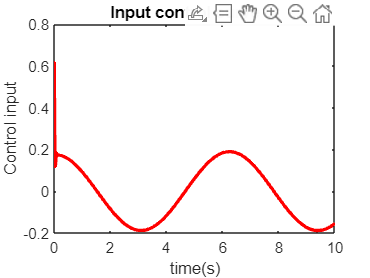


clf
figure(2);
plot(t,ut(:,1),'r','linewidth',2);
xlabel('time(s)');ylabel('Control input');
title('Input control curve ut')

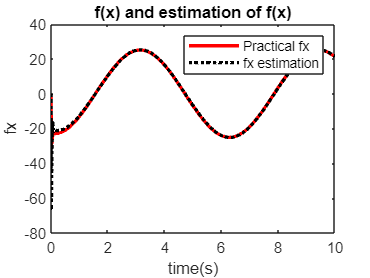


clf
figure(3);
plot(t,fx(:,1),'r',t,fx(:,2),'k:','linewidth',2);
xlabel('time(s)');ylabel('fx');
legend('Practical fx','fx estimation');
title('f(x) and estimation of f(x)')

#### 8.1.2 Second example NonLinear System

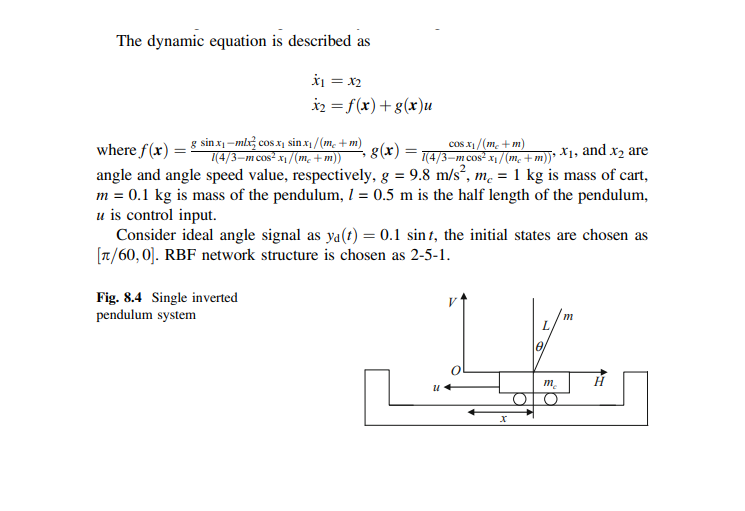

% The plant is considered bellow
imshow(imread("Adaptive_RBF_neural_network_approximation_nonlinear_system.png"));

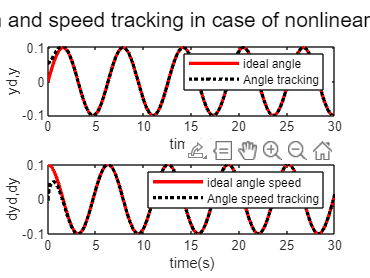


% the ideal position signal yd(t) = 0.1*sin(t)
% the initial states of the plant [pi/60,0]
% RBF network structure is 2-5-1
% cj = [-2 -1 0 1 2;-2 1 0 1 2] and bj = 0.2
% The initial value is chosen as zero

% Q = [500 0;0 500]; kd = 50, kp = 30, delta = 1200

% First see and run Simulink file sim_adaptive_rbf_nonlinear_system.slx
x = out.x;
ut = out.ut;
y = out.y;
fx = out.fx;
t = out.t;

close all;
figure(1);
subplot(211);
plot(t,0.1*sin(t),'r',t,y(:,1),'k:','linewidth',2);
xlabel('time(s)');ylabel('yd,y');
legend('ideal angle','Angle tracking');
subplot(212);
plot(t,0.1*cos(t),'r',t,y(:,2),'k:','linewidth',2);
xlabel('time(s)');ylabel('dyd,dy');
legend('ideal angle speed','Angle speed tracking');
sgtitle('Position and speed tracking in case of nonlinear system')

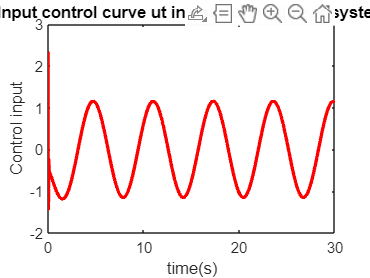


clf
figure(2);
plot(t,ut(:,1),'r','linewidth',2);
xlabel('time(s)');ylabel('Control input');
title('Input control curve ut in case of nonlinear system')

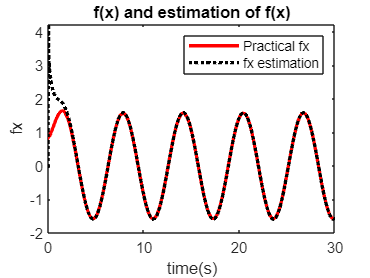


figure(3);
plot(t,fx(:,1),'r',t,fx(:,2),'k:','linewidth',2);
xlabel('time(s)');ylabel('fx');
legend('Practical fx','fx estimation');
title('f(x) and estimation of f(x)')

### 8.2  Adaptive Control based on Neural Approximation with unknown parameter

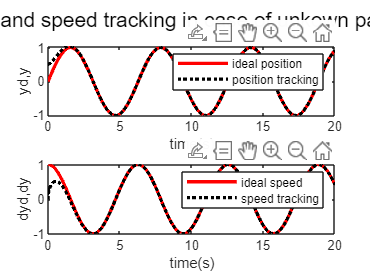

% Problem description
imshow(imread("Adaptive_RBF_neural_network_approximation_with_unknown_parameter.png"));

% Simulation example
imshow(imread("Simulation_example_Adaptive_RBF_neural_network_approximation_with_unknown_parameter.png"));

% x1 is the position and x2 is the speed
% u is the control input 
% f(x) = -25*x2 - 10*x1 and m = 133
% the ideal position signal yd(t) = sin(t)
% the initial states of the plant [0.5,0]
% RBF network structure is 2-5-1
% cj = [-1 -0.5 0 0.5 1] and bj = 2
% The initial value is chosen as zero

% Q = [500 0;0 500]; kd = 50, kp = 30, delta = 1200

% First see and run Simulink file sim_adaptive_rbf_with_unkown_parameter.slx

ut = out.ut;
y = out.y;
p = out.p;
t = out.t;

close all;

figure(1);
subplot(211);
plot(t,sin(t),'r',t,y(:,1),'k:','linewidth',2);
xlabel('time(s)');ylabel('yd,y');
legend('ideal position','position tracking');
subplot(212);
plot(t,cos(t),'r',t,y(:,2),'k:','linewidth',2);
xlabel('time(s)');ylabel('dyd,dy');
legend('ideal speed','speed tracking');
sgtitle('Position and speed tracking in case of unkown parameter')

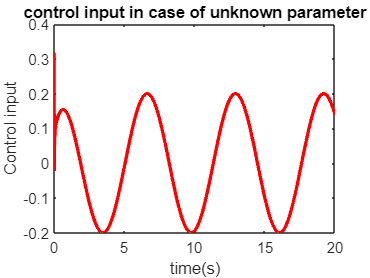


clf
figure(2);
plot(t,ut(:,1),'r','linewidth',2);
xlabel('time(s)');ylabel('Control input');
title('control input in case of unknown parameter')

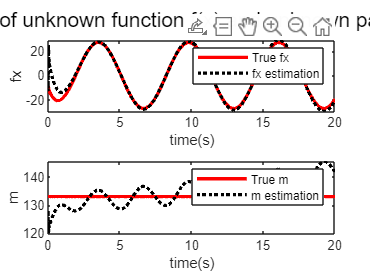


clf
figure(3);
subplot(211);
plot(t,p(:,1),'r',t,p(:,4),'k:','linewidth',2);
xlabel('time(s)');ylabel('fx');
legend('True fx','fx estimation');
subplot(212);
plot(t,p(:,2),'r',t,p(:,5),'k:','linewidth',2);
xlabel('time(s)');ylabel('m');
legend('True m','m estimation');
sgtitle('Estimation of unknown function f(x) and unknown parameter m')

## Chapter 9: Adaptive Sliding mode RBF Neural Network Control

### 9.1 Sliding mode Control Based on RBF for Second-Order SISO Nonlinear System

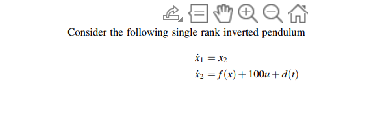

% The plant is considered bellow
close all;
figure(4)
imshow(imread("Sliding_mode_Control_Based_on_RBF_for_Second_Order_SISO_Nonlinear_System.png"));

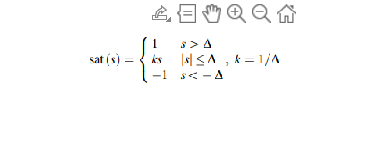


% x1 is the angle and x2 is angle speed
% u is the control input
% f(x) = x1 + x2 and d(t) = cos(t)
% the desired trajectory is xd(t) = sin(t)
% the initial states of the plant [0.2,0]
% control law c = 10, adaptive law neta = 10 and adaptive parameter delta = 0.01
% To eliminate chattering we use saturation function to replace sign
% function with Capital_delta = 0.05
figure(5)
imshow(imread("saturation_function.png"));

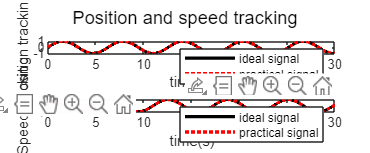


% RBF network structure is 2-5-1
% cj = [-1 -0.5 0 0.5 1;-1 -0.5 0 0.5 1] and bj = 5.0
% The initial value of weights is chosen as 0.1

% First see and run simulink file
% Simulation_sliding_mode_control_single_rank_inverted_pendulum.slx


ut = out.ut;
y = out.y;
t = out.t;
fx = out.fx;

clf
figure(1);
subplot(211);
plot(t,sin(t),'k',t,y(:,1),'r:','linewidth',2);
xlabel('time(s)');ylabel('Position tracking');
legend('ideal signal','practical signal');
subplot(212);
plot(t,cos(t),'k',t,y(:,2),'r:','linewidth',2);
xlabel('time(s)');ylabel('Speed tracking');
legend('ideal signal','practical signal');
sgtitle('Position and speed tracking');

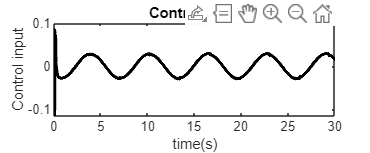


clf
figure(2);
plot(t,ut(:,1),'k','linewidth',2);
xlabel('time(s)');ylabel('Control input');
title('Control input');

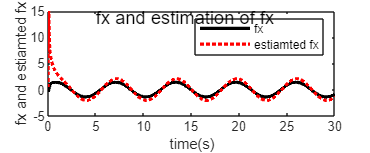


clf
figure(3);
plot(t,fx(:,1),'k',t,fx(:,2),'r:','linewidth',2);
xlabel('time(s)');ylabel('fx and estiamted fx');
legend('fx','estiamted fx');
sgtitle('fx and estimation of fx');

### 9.2 RBF Neural Robot Controller Design with Sliding Mode Robust Term

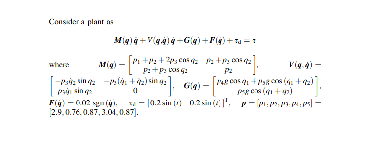

% The plant is considered bellow
close all;
figure(1)
imshow(imread("Robot_Control_Sliding_mode.png"));

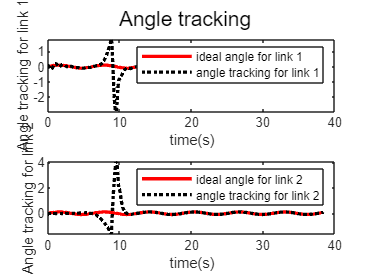


% the input is chosen as [e,de/dt]
% u is the control input
% the desired trajectory is q1d = 0.1sin(t) and q2d = 0.1sin(t)
% the initial states of the plant [0.09 0 -0.09 0]
% control law and adaptive law  Kv = diag{10,10}; C = diag{15,15} ; K = diag{5,5}

% RBF network structure is 2-7-1
% cj = [-1.5 -1 -0.5 0 0.5 1 1.5;-1.5 -1 -0.5 0 0.5 1 1.5] and bj = 10
% The initial value of weights is chosen as zero

% First see and run simulink file
% sim_RBF_Neural_Robot_Controller_Design_with_Sliding.slx

qd = out.qd;
q = out.q;
f = out.f;
tol1 = out.tol1;
tol2 = out.tol2;
t = out.t;

clf
figure(2);
subplot(211);
plot(t,qd(:,1),'r',t,q(:,1),'k:','linewidth',2);
xlabel('time(s)');ylabel('Angle tracking for link 1');
legend('ideal angle for link 1','angle tracking for link 1');
subplot(212);
plot(t,qd(:,4),'r',t,q(:,3),'k:','linewidth',2);
xlabel('time(s)');ylabel('Angle tracking for link 2');
legend('ideal angle for link 2','angle tracking for link 2');
sgtitle('Angle tracking')

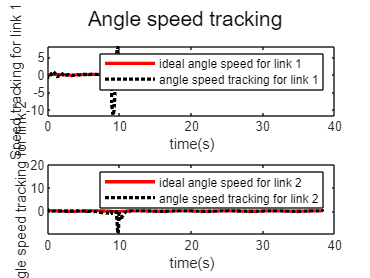


clf
figure(3);
subplot(211);
plot(t,qd(:,2),'r',t,q(:,2),'k:','linewidth',2);
xlabel('time(s)');ylabel('Speed tracking for link 1');
legend('ideal angle speed for link 1','angle speed tracking for link 1');
subplot(212);
plot(t,qd(:,5),'r',t,q(:,4),'k:','linewidth',2);
xlabel('time(s)');ylabel('Angle speed tracking for link 2');
legend('ideal angle speed for link 2','angle speed tracking for link 2');
sgtitle('Angle speed tracking')

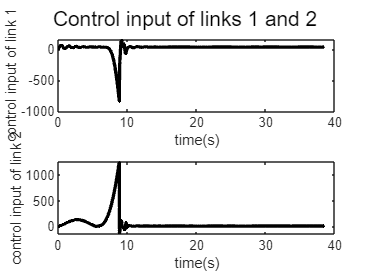


clf
figure(4);
subplot(211);
plot(t,tol1(:,1),'k','linewidth',2);
xlabel('time(s)');ylabel('control input of link 1');
subplot(212);
plot(t,tol2(:,1),'k','linewidth',2);
xlabel('time(s)');ylabel('control input of link 2');
sgtitle('Control input of links 1 and 2')

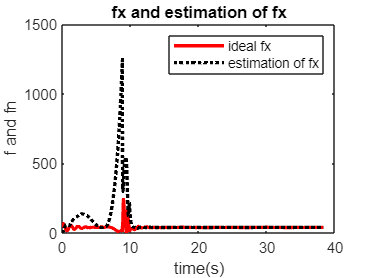


clf
figure(5);
plot(t,f(:,1),'r',t,f(:,2),'k:','linewidth',2);
xlabel('time(s)');ylabel('f and fn');
legend('ideal fx','estimation of fx');
title('fx and estimation of fx')

## Chapter 10: Discrete RBF Neural Network Control

### 10.1 Digital Adaptive RBF Control for a Continuous system

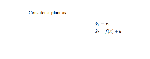

% The plant is considered bellow
close all;
figure(1)
imshow(imread("plant_digital_adaptive_RBF_control.png"));

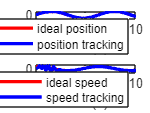


% f(x) = 10*x1*x2
% u is the control input
% the desired trajectory is xd = sin(t)
% The initial state of plant is [0.5 0]
% the initial states of the plant [0.09 0 -0.09 0]
% control law and adaptive law  lambda = 200; neta = 0.2; delta = 100
% sampling time ts = 0.001

% RBF network structure is 2-5-1
% cj = [-1 -0.5 0 0.5 1;-1 -0.5 0 0.5 1] and bj = 3
% The initial value of weights is chosen as zero

% First see and run simulink file
% Digital_Adaptive_RBF_Control_For_Continuous_System.slx

x = out.x;
f = out.f;
t = out.t;

clf
figure(2);
subplot(211);
plot(t,x(:,1),'r',t,x(:,2),'b','linewidth',2);
xlabel('time(s)');ylabel('position tracking');
legend('ideal position','position tracking');
subplot(212);
plot(t,cos(t),'r',t,x(:,3),'b','linewidth',2);
xlabel('time(s)');ylabel('speed tracking');
legend('ideal speed','speed tracking');

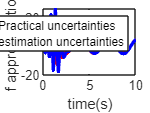


clf
figure(3);
plot(t,f(:,1),'r',t,f(:,3),'b','linewidth',2);
xlabel('time(s)');ylabel('f approximation');
legend('Practical uncertainties','estimation uncertainties')

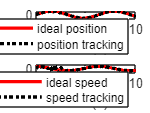

%% Digital simulation program
% Same program for continuous plant but here the plant is discrete

%Discrete RBF control
clear all;
close all;
ts=0.001; %Sampling time

node=5; %Number of neural nets in hidden layer
gama=100;

c=[-1 -0.5 0 0.5 1;
   -1 -0.5 0 0.5 1];
bj=1.2;
h=zeros(node,1);
x1_1=0;x2_1=0;u_1=0;

xk=[0.10 0];
w_1=rands(node,1);
namna=10;
xite=0.20;

for k=1:1:10000
    time(k)=k*ts;
    
    xd(k)=sin(k*ts);
    dxd(k)=cos(k*ts);
    ddxd(k)=-sin(k*ts);
    
    tSpan=[0 ts];
    para=u_1; %D/A
    [t,xx]=ode45('digital_plant',tSpan,xk,[],para); %Plant
    xk=xx(length(xx),:); %A/D
    
    x1(k)=xk(1);
    x2(k)=xk(2);
    
    e(k)=x1(k)-xd(k);
    de(k)=x2(k)-dxd(k);
    s(k)=namna*e(k)+de(k);
    
    xi=[x1(k);x2(k)];
    for i=1:1:node
        w(i,1)=w_1(i,1)+ts*(gama*s(k)*h(i)); %Adaptive law
    end
    h=zeros(5,1);
    for j=1:1:5
        h(j)=exp(-norm(xi-c(:,j))^2/(2*bj*bj));
    end
    fn(k)=w'*h;
    u(k)=-namna*de(k)-fn(k)+ddxd(k)-xite*sign(s(k));
    
    f(k)=10*x1(k)*x2(k);
    
    x1_1=x1(k);
    x2_1=x2(k);
    w_1=w;
    u_1=u(k);
end

clf
figure(1);
subplot(211);
plot(time,xd,'r',time,x1,'k:','linewidth',2);
xlabel('time(s)');ylabel('Position tracking');
legend('ideal position','position tracking');
subplot(212);
plot(time,dxd,'r',time,x2,'k:','linewidth',2);
xlabel('time(s)');ylabel('Speed tracking');
legend('ideal speed','speed tracking');

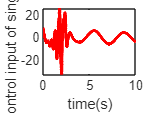


clf
figure(2);
plot(time,u,'r','linewidth',2);
xlabel('time(s)'),ylabel('Control input of single link');

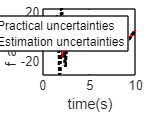


clf
figure(3);
plot(time,f,'r',time,fn,'k:','linewidth',2);
xlabel('time(s)'),ylabel('f and fn');
legend('Practical uncertainties','Estimation uncertainties');

### 10.2 Adaptive RBF Control for a Class of Discrete-Time Nonlinear System

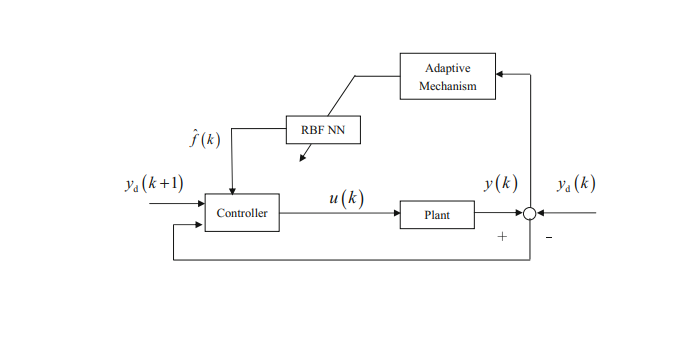

% The block diagram for controlling discrete-time nonlinear system
close all;
figure(1)
imshow(imread("block_diagram_control_Discrete_nonlinear_system.png"));

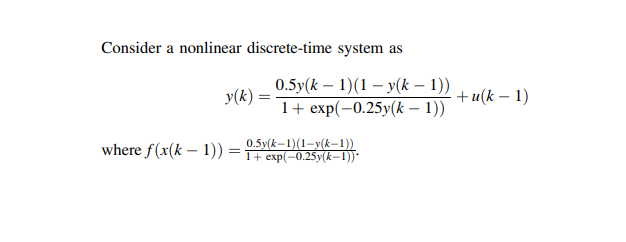


% The plant is considered bellow

figure(2)
imshow(imread("nonlinear_discrete_time_system.png"));

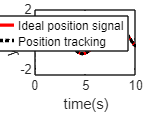


% f(x(k-1)) is known
% u is the control input
% the desired trajectory is yd(k) = sin(t)
% The initial state of plant is [0.5 0]
% the initial states of the plant [0.09 0 -0.09 0]
% control law and adaptive law c1 = -0.01, beta = 0.001, delta = 0.001, G = 50000, epsilon_f = 0.003

% RBF network structure is 1-9-1
% cj = [-2 -1.5 -1.0 -0.5 0 0.5 1 1.5 2] and bj = 15
% The initial value of weights is chosen as random value in [0,1]

%Discrete RBF controller
clear all;
close all;
ts=0.001;
c1=-0.01;
beta=0.001;
epcf=0.003;
gama=0.001;
G=50000;

b=15;
c=[-2 -1.5 -1 -0.5 0 0.5 1 1.5 2];
w=rands(9,1);
w_1=w;

u_1=0;
y_1=0;
e1_1=0;
e_1=0;
fx_1=0;

for k=1:1:10000
    time(k)=k*ts;
    
    yd(k)=sin(k*ts);
    yd1(k)=sin((k+1)*ts);
    %Nonlinear plant
    fx(k)=0.5*y_1*(1-y_1)/(1+exp(-0.25*y_1));
    y(k)=fx_1+u_1;
    
    e(k)=y(k)-yd(k);
    x(1)=y_1;
    for j=1:1:9
        h(j)=exp(-norm(x-c(:,j))^2/(2*b^2));
    end
    v1_bar(k)=beta/(2*gama*c1^2)*h*h';
    
    e1(k)=(-c1*e1_1+beta*(e(k)+c1*e_1))/(1+beta*(v1_bar(k)+G));
    if abs(e1(k))>epcf/G
        w=w_1+beta/(gama*c1^2)*h'*e1(k);
    elseif abs(e1(k))<=epcf/G
        w=w_1;
    end
    fnn(k)=w'*h';
    
    u(k)=yd1(k)-fnn(k)-c1*e(k);
    %u(k)=yd1(k)-fx(k)-c1*e(k); %With precise fx
    
    fx_1=fx(k);
    y_1=y(k);
    
    w_1=w;
    u_1=u(k);
    e1_1=e1(k);
    e_1=e(k);
end

figure(3);
plot(time,yd,'r',time,y,'k:','linewidth',2);
xlabel('time(s)');ylabel('yd,y');
legend('Ideal position signal','Position tracking');

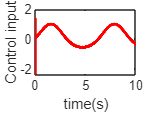


figure(4);
plot(time,u,'r','linewidth',2);
xlabel('time(s)');ylabel('Control input');

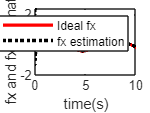


figure(5);
plot(time,fx,'r',time,fnn,'k:','linewidth',2);
xlabel('time(s)');ylabel('fx and fx estimation');
legend('Ideal fx','fx estimation');

## Chapter 11 Intelligent Search Algorithm Design

### 11.1 Genetic Algorithms (GA)

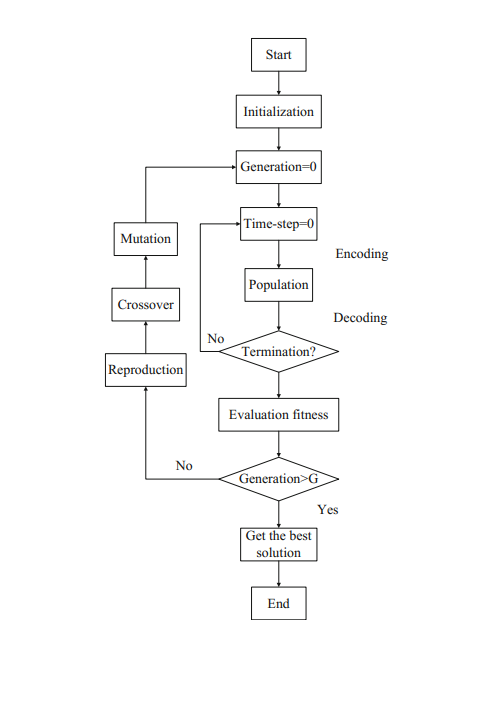

% flowchart for GA
close all;
figure(1)
imshow(imread("flowchart_GA.png"));

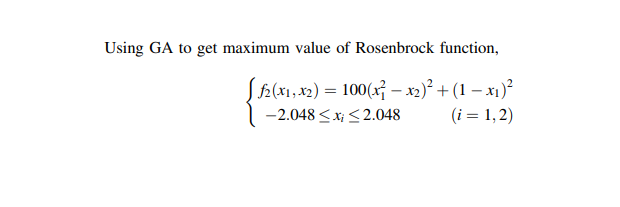


% Find the maximum value of Rosenbrock function below using Genetic
% Algoritm

figure(2)
imshow(imread("Rosenbrock_function.png"));

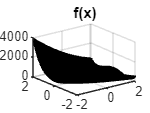


% We have f(2.048,-2.048) = 3897.7342 and f(-2.048,-2.048) = 3905.9262

% First we use 10-bit genes to code xi, -2.048 is coded as 0000000000 (0)
% and 2.048 1111111111 (1023) and [x1,x2] is coded as 20-bit gene for
% example 0000110111 1101110001

% Secondly decode 20-bit binary gene to 2 10-bit binary genes x1 and x2 and change
% them to decimal system y1 and y2 using the following relationship
% xi = 4.096 * (yi/1023) - 2.048
% For example x:  0000110111 1101110001 can be decoded as y1 = 55 and
% y2 = 881 so x1 = -1.828 and x2 = 1.476

% Thirdly we evaluate fitness function F(x) = f(x1,x2) then we get the
% objective function as J(x) = 1/F(x)

% Fourtly, Fourthly, design operators, including proportion selection operator,single-point
% crossover operator,and basic bit mutation operator, and choose parameters of GA as

% For simulation we choose: Population size = 80, Generation G = 100,
% crossover probability Pc = 0.6, mutation probability Pm = 0.1

% We found that maximum value of Rosenbrock function is 3905.9 for
% x1 = -2.048 and x2 = -2.048

% The shape of Rosenbrock function
clear all;
close all;

x_min=-2.048;
x_max=2.048;

L=x_max-x_min;
N=101;
for i=1:1:N
    for j=1:1:N
        x1(i)=x_min+L/(N-1)*(i-1); %set 100 points in x1 axis
        x2(j)=x_min+L/(N-1)*(j-1); %set 100 points in x2 axis
        fx(i,j)=100*(x1(i)^2-x2(j))^2+(1-x1(i))^2;
    end
end
figure(1);
surf(x1,x2,fx);
title('f(x)');

display('Maximum value of fx=');

Maximum value of fx=


disp(max(max(fx)));

   3.9059e+03



%Generic Algorithm for function f(x1,x2) optimum
clear all;
close all;

%Parameters
Size=80;
G=100;
CodeL=10;

umax=2.048;
umin=-2.048;

E=round(rand(Size,2*CodeL)); %Initial Code

%Main Program
for k=1:1:G
    time(k)=k;
    for s=1:1:Size
        m=E(s,:);
        y1=0;y2=0;
        
        %Uncoding
        m1=m(1:1:CodeL);
        
        for i=1:1:CodeL
            y1=y1+m1(i)*2^(i-1);
        end
        
        x1=(umax-umin)*y1/1023+umin;
        m2=m(CodeL+1:1:2*CodeL);
        
        for i=1:1:CodeL
            y2=y2+m2(i)*2^(i-1);
        end
        
        x2=(umax-umin)*y2/1023+umin;
        
        F(s)=100*(x1^2-x2)^2+(1-x1)^2;
    end
    
    Ji=1./F;
    
    %******Step 1 : Evaluate BestJ******
    BestJ(k)=min(Ji);
    
    fi=F; %Fitness Function
    [Oderfi,Indexfi]=sort(fi); %Arranging fi small to bigger
    Bestfi=Oderfi(Size); %Let Bestfi=max(fi)
    BestS=E(Indexfi(Size),:); %Let BestS=E(m), m is the Indexfi belong to max(fi)
    bfi(k)=Bestfi;
    
    %******Step 2 : Select and Reproduct Operation******
    fi_sum=sum(fi);
    fi_Size=(Oderfi/fi_sum)*Size;
    
    fi_S=floor(fi_Size); %Selecting Bigger fi value
    
    kk=1;
    
    for i=1:1:Size
        for j=1:1:fi_S(i) %Select and Reproduce
            TempE(kk,:)=E(Indexfi(i),:);
            kk=kk+1; %kk is used to reproduce
        end
    end
    
    %************ Step 3 : Crossover Operation ************
    pc=0.60;
    n=ceil(20*rand);
    for i=1:2:(Size-1)
        temp=rand;
        if pc>temp %Crossover Condition
            for j=n:1:20
                TempE(i,j)=E(i+1,j);
                TempE(i+1,j)=E(i,j);
            end
        end
    end
    TempE(Size,:)=BestS;
    E=TempE;
    
    %************ Step 4: Mutation Operation **************
    %pm=0.001;
    %pm=0.001-[1:1:Size]*(0.001)/Size; %Bigger fi, smaller Pm
    %pm=0.0; %No mutation
    pm=0.1; %Big mutation
    
    for i=1:1:Size
        for j=1:1:2*CodeL
            temp=rand;
            if pm>temp %Mutation Condition
                if TempE(i,j)==0
                    TempE(i,j)=1;
                else
                    TempE(i,j)=0;
            end
        end
    end
end
%Guarantee TempPop(30,:) is the code belong to the best individual(max(fi))
    TempE(Size,:)=BestS;
    E=TempE;
end

Max_Value=Bestfi

Max_Value = 3.9059e+03

BestS

BestS =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x1

x1 = -2.0480

x2

x2 = -2.0480

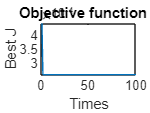


clf
figure(1);
plot(time,BestJ);
xlabel('Times');ylabel('Best J');
title('Objective function J')

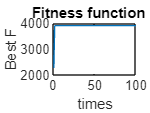


clf
figure(2);
plot(time,bfi);
xlabel('times');ylabel('Best F');
title('Fitness function F')

### 11.2 Particle Swarm Optimization Algorithms (PSO) 

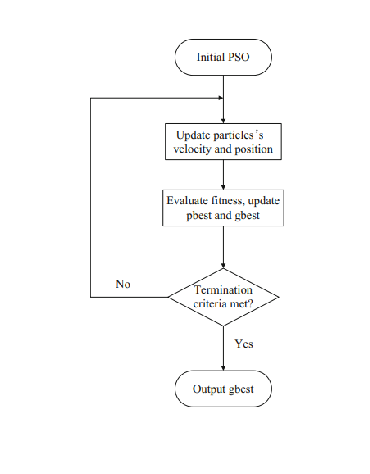

% flowchart for PSO
close all;
figure(1)
imshow(imread("flowchart_PSO.png"));

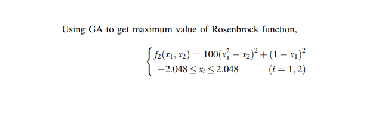


% Find the maximum value of Rosenbrock function below using Genetic
% Algoritm
clf
figure(2)
imshow(imread("Rosenbrock_function.png"));

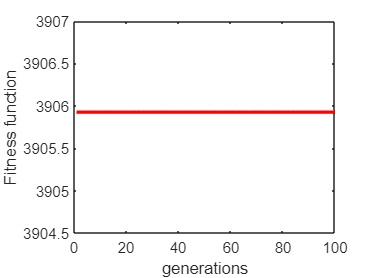


% We have two local maximum f(2.048,-2.048) = 3897.7342 and f(-2.048,-2.048) = 3905.9262
% And a global maximum f(-2.048,-2.048) = 3905.9262

% in this example we choose 8 particvles to illustrate local PSO algorithm

% The speed and position of each particle areupdated as follow:
clf
figure(3)
imshow(imread("annular_neighborhood_method.png"));

% Real encoding of decision variables x1 and x2 is used to discretize these
% decision variables from -2.048 to 2.048
% Fitness function is F(x) = f(x1,x2)

% The number of particles is 50, the maximum number of iteration is G = 100
% maximum velocity of particle is Vmax = 1.0 and velocity range is [-1,1]
% The learning factors are c1 = 1.3 and c2 = 1.7, the weight values are
% decreasing from 0.9 to 0.1

% M = 1 is for local PSO and M = 2 is for global PSO

clear all;
close all;
%(1)Initialize PSO
min=-2.048;max=2.048;
Vmax=1;Vmin=-1;
c1=1.3;c2=1.7;
wmin=0.10;wmax=0.90;
G=100;
Size=50;

for i=1:G
    w(i)=wmax-((wmax-wmin)/G)*i;
end

for i=1:Size
    for j=1:2
        x(i,j)=min+(max-min)*rand(1);
        v(i,j)=Vmin +(Vmax-Vmin)*rand(1);
    end
end

%(2) Calculte fitness
for i=1:Size
    p(i)=func(x(i,:));
    y(i,:)=x(i,:);
    if i==1
        plocal(i,:)=evaluate_localbest(x(Size,:),x(i,:),x(i+1,:));
    elseif i==Size
        plocal(i,:)=evaluate_localbest(x(i-1,:),x(i,:),x(1,:));
    else
        plocal(i,:)=evaluate_localbest(x(i-1,:),x(i,:),x(i+1,:));
    end
end

BestS=x(1,:);
for i=2:Size
    if func(x(i,:))>func(BestS)
        BestS=x(i,:);
    end
end

%(3) Main loop
for kg=1:G
        for i=1:Size
            M=1;
            if M==1
                v(i,:)=w(kg)*v(i,:)+c1*rand*(y(i,:)-x(i,:))+c2*rand*(plocal(i,:)-x(i,:));%Local optimization
            elseif M==2
                v(i,:)=w(kg)*v(i,:)+c1*rand*(y(i,:)-x(i,:))+c2*rand*(BestS-x(i,:)); %Global optimization
            end
            for j=1:2 %Judge the limit of velocity
                if v(i,j)<Vmin
                    v(i,j)=Vmin;
                elseif x(i,j)>Vmax
                    v(i,j)=Vmax;
                end
            end
            x(i,:)=x(i,:)+v(i,:)*1; %Update position
            for j=1:2 %Check the limit
                if x(i,j)<min
                    x(i,j)=min;
                elseif x(i,j)>max
                    x(i,j)=max;
                end
            end
        %Adaptive mutation
            if rand>0.60
                k=ceil(2*rand);
                x(i,k)=min+(max-min)*rand(1);
            end
        %(4)Judge and update
            if i==1
                plocal(i,:)=evaluate_localbest(x(Size,:),x(i,:),x(i+1,:));
            elseif i==Size
                plocal(i,:)=evaluate_localbest(x(i-1,:),x(i,:),x(1,:));
            else
                plocal(i,:)=evaluate_localbest(x(i-1,:),x(i,:),x(i+1,:));
            end
        
            if func(x(i,:))>p(i) %Judge and update
                p(i)=func(x(i,:));
                y(i,:)=x(i,:);
            end
            if p(i)>func(BestS)
                BestS=y(i,:);
            end
        end
        Best_value(kg)=func(BestS);
end

clf
figure(4);
kg=1:G;
plot(kg,Best_value,'r','linewidth',2);
xlabel('generations');ylabel('Fitness function');

display('Best Sample=');disp(BestS);

Best Sample=
   -2.0480   -2.0480



display('Biggest value=');disp(Best_value(G));

Biggest value=
   3.9059e+03



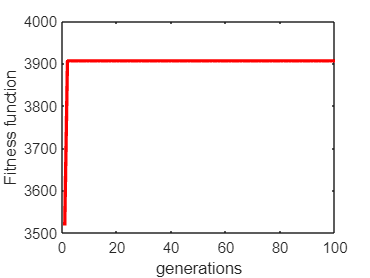

% global PSO

clear all;
close all;
%(1)Initialize PSO
min=-2.048;max=2.048;
Vmax=1;Vmin=-1;
c1=1.3;c2=1.7;
wmin=0.10;wmax=0.90;
G=100;
Size=50;

for i=1:G
    w(i)=wmax-((wmax-wmin)/G)*i;
end

for i=1:Size
    for j=1:2
        x(i,j)=min+(max-min)*rand(1);
        v(i,j)=Vmin +(Vmax-Vmin)*rand(1);
    end
end

%(2) Calculte fitness
for i=1:Size
    p(i)=func(x(i,:));
    y(i,:)=x(i,:);
    if i==1
        plocal(i,:)=evaluate_localbest(x(Size,:),x(i,:),x(i+1,:));
    elseif i==Size
        plocal(i,:)=evaluate_localbest(x(i-1,:),x(i,:),x(1,:));
    else
        plocal(i,:)=evaluate_localbest(x(i-1,:),x(i,:),x(i+1,:));
    end
end

BestS=x(1,:);
for i=2:Size
    if func(x(i,:))>func(BestS)
        BestS=x(i,:);
    end
end

%(3) Main loop
for kg=1:G
        for i=1:Size
            M=2;
            if M==1
                v(i,:)=w(kg)*v(i,:)+c1*rand*(y(i,:)-x(i,:))+c2*rand*(plocal(i,:)-x(i,:));%Local optimization
            elseif M==2
                v(i,:)=w(kg)*v(i,:)+c1*rand*(y(i,:)-x(i,:))+c2*rand*(BestS-x(i,:)); %Global optimization
            end
            for j=1:2 %Judge the limit of velocity
                if v(i,j)<Vmin
                    v(i,j)=Vmin;
                elseif x(i,j)>Vmax
                    v(i,j)=Vmax;
                end
            end
            x(i,:)=x(i,:)+v(i,:)*1; %Update position
            for j=1:2 %Check the limit
                if x(i,j)<min
                    x(i,j)=min;
                elseif x(i,j)>max
                    x(i,j)=max;
                end
            end
        %Adaptive mutation
            if rand>0.60
                k=ceil(2*rand);
                x(i,k)=min+(max-min)*rand(1);
            end
        %(4)Judge and update
            if i==1
                plocal(i,:)=evaluate_localbest(x(Size,:),x(i,:),x(i+1,:));
            elseif i==Size
                plocal(i,:)=evaluate_localbest(x(i-1,:),x(i,:),x(1,:));
            else
                plocal(i,:)=evaluate_localbest(x(i-1,:),x(i,:),x(i+1,:));
            end
        
            if func(x(i,:))>p(i) %Judge and update
                p(i)=func(x(i,:));
                y(i,:)=x(i,:);
            end
            if p(i)>func(BestS)
                BestS=y(i,:);
            end
        end
        Best_value(kg)=func(BestS);
end

clf
figure(4);
kg=1:G;
plot(kg,Best_value,'r','linewidth',2);
xlabel('generations');ylabel('Fitness function');

display('Best Sample=');disp(BestS);

Best Sample=
   -2.0480   -2.0480



display('Biggest value=');disp(Best_value(G));

Biggest value=
   3.9059e+03



### 11.3 Differential Evolution Algorithm (DE) 

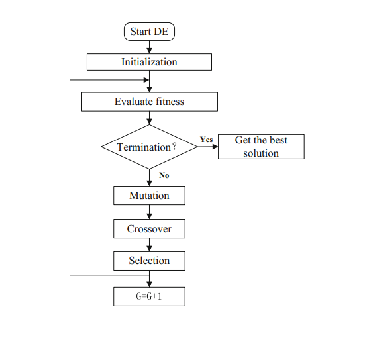

% flowchart for PSO
close all;
figure(1)
imshow(imread("flowchart_DE.png"));


% Find the maximum value of Rosenbrock function below using Genetic
% Algoritm
clf
figure(2)
imshow(imread("Rosenbrock_function.png"));


% Real encoding of decision variables x1 and x2 is used to discretize these
% decision variables from -2.048 to 2.048
% Fitness function is F(x) = f(x1,x2)

% The number of particles is 30, the maximum number of iteration is G = 50
% F = 1.2 and CR = 1.9

%To Get maximum value of function f(x1,x2) by Differential Evolution
clear all;
close all;

Size=30;
CodeL=2;

MinX(1)=-2.048;
MaxX(1)=2.048;
MinX(2)=-2.048;
MaxX(2)=2.048;

G=50;

F=1.2; %[0,2]
cr=0.9; %[0.6,0.9]
% Initialization
for i=1:1:CodeL
    P(:,i)=MinX(i)+(MaxX(i)-MinX(i))*rand(Size,1);
end

BestS=P(1,:); % Best individual
for i=2:Size
    if(evaluate_objective( P(i,1),P(i,2))>evaluate_objective( BestS(1),BestS(2)))
        BestS=P(i,:);
    end
end
fi=evaluate_objective(BestS(1),BestS(2));

for kg=1:1:G
    time(kg)=kg;
    %mutation
    for i=1:Size
        r1 = 1;r2=1;r3=1;
        while(r1 == r2|| r1 == r3 || r2 == r3 || r1 == i || r2 ==i || r3 == i )
            r1 = ceil(Size * rand(1));
            r2 = ceil(Size * rand(1));
            r3 = ceil(Size * rand(1));
        end
        h(i,:) = P(r1,:)+F*(P(r2,:)-P(r3,:));
        
        for j=1:CodeL %Check limit
            if h(i,j)<MinX(j)
                h(i,j)=MinX(j);
            elseif h(i,j)>MaxX(j)
                h(i,j)=MaxX(j);
            end
        end
    %crossover
        for j = 1:1:CodeL
            tempr = rand(1);
            if(tempr<cr)
                v(i,j) = h(i,j);
            else
                v(i,j) = P(i,j);
            end
        end
    %selection
        if(evaluate_objective( v(i,1),v(i,2))>evaluate_objective( P(i,1),P(i,2)))
            P(i,:)=v(i,:);
        end
    %Judge and update
        if(evaluate_objective( P(i,1),P(i,2))>fi)
            fi=evaluate_objective( P(i,1),P(i,2));
            BestS=P(i,:);
        end
    end
    Best_f(kg)=evaluate_objective( BestS(1),BestS(2));
end
BestS % Best individual

BestS =    -2.0480   -2.0480


Best_f(kg) %Biggest value

ans = 3.9059e+03

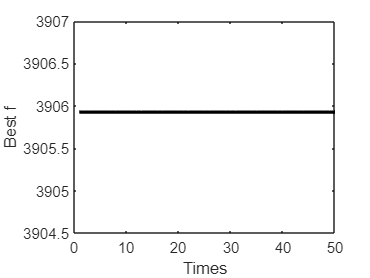


clf
figure(3);
plot(time,Best_f(time),'k','linewidth',2);
xlabel('Times');ylabel('Best f');

### 11.4 Traveling Saleman Problem (TSP) Optimization based on Hopfield Neural Network 

% We choose A = 1.5 and D = 1.0 and Sampling time ts = 0.01
% The initial value of neural network is random value from [-1,1]
% mu = 50 and activation function is Sigmoid
% Number of iterations is 2000, the optimal energy function E_final = 1.4468
% the initial distance Initial_Length = 4.1419
% The shortest distance is final_Length = 2.8937

% TSP Solving by Hopfield Neural Network

clear all;
close all;

%Step 1: Initialization
A=1.5;
D=1;
Mu=50;
Step=0.01;

%Step 2: %Calculate initial route length
N=8;
cityfile = fopen('city8.txt','rt' );
cities = fscanf(cityfile, '%f %f',[ 2,inf] )

cities =     0.1000    0.9000    0.9000    0.4500    0.9000    0.7000    0.1000    0.4500
    0.1000    0.5000    0.1000    0.9000    0.8000    0.9000    0.4500    0.1000


fclose(cityfile);
Initial_Length=Initial_RouteLength(cities);

DistanceCity=dist(cities',cities);
%Step 3: Initialization NN
U=rands(N,N);
V=1./(1+exp(-Mu*U)); % S function

for k=1:1:2000
    times(k)=k;
%Step 4: Calculate du/dt
    dU=DeltaU(V,DistanceCity,A,D);
%Step 5: Calculate u(t)
    U=U+dU*Step;
%Step 6: Calculate output of NN
    V=1./(1+exp(-Mu*U)); % S function
%Step 7: Calculate energy function
    E=Energy(V,DistanceCity,A,D);
    Ep(k)=E;
%Step 8: Check validity of the route
    [V1,CheckR]=RouteCheck(V);
end
%Step 9: Results
if(CheckR==0)
    Final_E=Energy(V1,DistanceCity,A,D);
    Final_Length=Final_RouteLength(V1,cities); %Give final length
    disp('Iteration times');k
    disp(' the optimization route is');V1
    disp('Final optimization engergy function:');Final_E
    disp('Initial length');Initial_Length
    disp('Final optimization length');Final_Length

    PlotR(V1,cities);
else
    disp('the optimization route is');V1
    disp('the route is invalid');
end

the optimization route is


V1 =      0     1     0     0     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     1
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0


the route is invalid


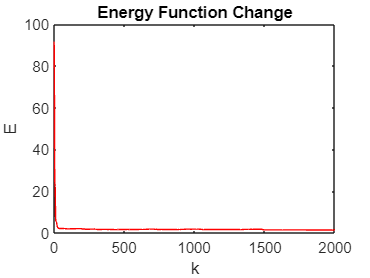


figure(2);
plot(times,Ep,'r');
title('Energy Function Change');
xlabel('k');ylabel('E');

## Chapter 12 Iterative Learning Control and Application

### 12.1 ILC Simulation for Manipulator Trajectory Tracking

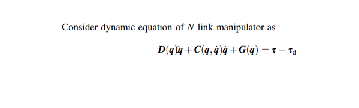

% The plant is considered below
close all;
clear all;
figure(1)
imshow(imread("N_link_manipulator.png"));

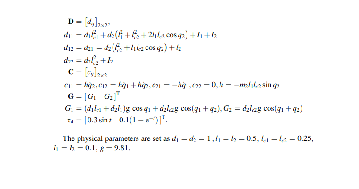


% The parameters of plant are below

figure(2)
imshow(imread("parameters_N_link_manipulator.png"));


% The ideal position of 2 joints is set as sin(3t) and cos(3t)
% We choose x(0) = [0 3 1 0]'
% Kp = [100 0;0 100] and Kd = [500 0;0 500]

%Adaptive switching Learning Control for 2DOF robot manipulators


t=[0:0.01:3]';
k(1:301)=0; %Total initial points
k=k';
T1(1:301)=0;
T1=T1';
T2=T1;
T=[T1 T2];

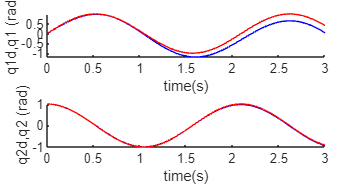

% D-type ILC
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% First see and run simulink file sim_control_two_DOF_robot_manipulator.slx


qd = out.qd;
T = out.T;
q = out.q;
k = out.k;
t = out.t;

N=20;

for i=0:1:N % Start Learning Control
    i;
    pause(0.01);
    
    sim('sim_control_two_DOF_robot_manipulator',[0,3]);
    
    q1=q(:,1);
    dq1=q(:,2);
    q2=q(:,3);
    dq2=q(:,4);
    
    q1d=qd(:,1);
    dq1d=qd(:,2);
    q2d=qd(:,3);
    dq2d=qd(:,4);
    
    e1=q1d-q1;
    e2=q2d-q2;
    de1=dq1d-dq1;
    de2=dq2d-dq2;
    
    clf
    figure(1);
    subplot(211);
    hold on;
    plot(t,q1,'b',t,q1d,'r');
    xlabel('time(s)');ylabel('q1d,q1 (rad)');
    subplot(212);
    hold on;
    plot(t,q2,'b',t,q2d,'r');
    xlabel('time(s)');ylabel('q2d,q2 (rad)');
    j=i+1;
    times(j)=i;
    e1i(j)=max(abs(e1));
    e2i(j)=max(abs(e2));
    de1i(j)=max(abs(de1));
    de2i(j)=max(abs(de2));
end %End of i

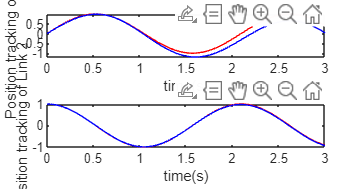

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clf
figure(2);
subplot(211);
plot(t,q1d,'r',t,q1,'b');
xlabel('time(s)');ylabel('Position tracking of Link 1');
subplot(212);
plot(t,q2d,'r',t,q2,'b');
xlabel('time(s)');ylabel('Position tracking of Link 2');

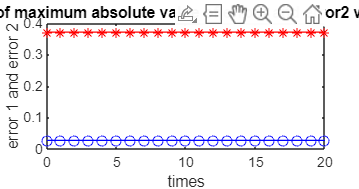


clf
figure(3);
plot(times,e1i,'*-r',times,e2i,'o-b');
title('Change of maximum absolute value of error1 and error2 with times i');
xlabel('times');ylabel('error 1 and error 2');

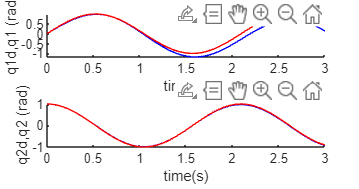

% PD-type ILC
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% First see and run simulink file sim_control_two_DOF_robot_manipulator.slx


qd = out.qd;
T = out.T;
q = out.q;
k = out.k;
t = out.t;

N=20;

for i=0:1:N % Start Learning Control
    i;
    pause(0.01);
    
    sim('sim_control_two_DOF_robot_manipulator',[0,3]);
    
    q1=q(:,1);
    dq1=q(:,2);
    q2=q(:,3);
    dq2=q(:,4);
    
    q1d=qd(:,1);
    dq1d=qd(:,2);
    q2d=qd(:,3);
    dq2d=qd(:,4);
    
    e1=q1d-q1;
    e2=q2d-q2;
    de1=dq1d-dq1;
    de2=dq2d-dq2;
    
    clf
    figure(1);
    subplot(211);
    hold on;
    plot(t,q1,'b',t,q1d,'r');
    xlabel('time(s)');ylabel('q1d,q1 (rad)');
    subplot(212);
    hold on;
    plot(t,q2,'b',t,q2d,'r');
    xlabel('time(s)');ylabel('q2d,q2 (rad)');
    j=i+1;
    times(j)=i;
    e1i(j)=max(abs(e1));
    e2i(j)=max(abs(e2));
    de1i(j)=max(abs(de1));
    de2i(j)=max(abs(de2));
end %End of i

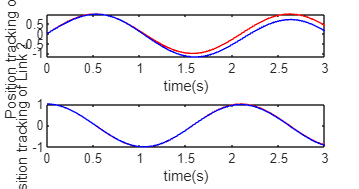

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clf
figure(2);
subplot(211);
plot(t,q1d,'r',t,q1,'b');
xlabel('time(s)');ylabel('Position tracking of Link 1');
subplot(212);
plot(t,q2d,'r',t,q2,'b');
xlabel('time(s)');ylabel('Position tracking of Link 2');

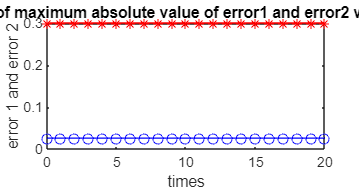


clf
figure(3);
plot(times,e1i,'*-r',times,e2i,'o-b');
title('Change of maximum absolute value of error1 and error2 with times i');
xlabel('times');ylabel('error 1 and error 2');

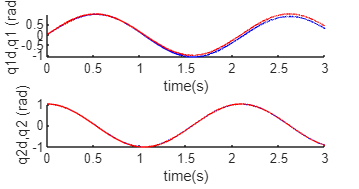

% Exponential Gain D-type ILC
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% First see and run simulink file sim_control_two_DOF_robot_manipulator.slx


qd = out.qd;
T = out.T;
q = out.q;
k = out.k;
t = out.t;

N=20;

for i=0:1:N % Start Learning Control
    i;
    pause(0.01);
    
    sim('sim_control_two_DOF_robot_manipulator',[0,3]);
    
    q1=q(:,1);
    dq1=q(:,2);
    q2=q(:,3);
    dq2=q(:,4);
    
    q1d=qd(:,1);
    dq1d=qd(:,2);
    q2d=qd(:,3);
    dq2d=qd(:,4);
    
    e1=q1d-q1;
    e2=q2d-q2;
    de1=dq1d-dq1;
    de2=dq2d-dq2;
    
    clf
    figure(1);
    subplot(211);
    hold on;
    plot(t,q1,'b',t,q1d,'r');
    xlabel('time(s)');ylabel('q1d,q1 (rad)');
    subplot(212);
    hold on;
    plot(t,q2,'b',t,q2d,'r');
    xlabel('time(s)');ylabel('q2d,q2 (rad)');
    j=i+1;
    times(j)=i;
    e1i(j)=max(abs(e1));
    e2i(j)=max(abs(e2));
    de1i(j)=max(abs(de1));
    de2i(j)=max(abs(de2));
end %End of i

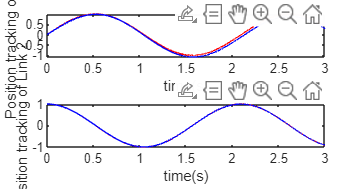

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clf
figure(2);
subplot(211);
plot(t,q1d,'r',t,q1,'b');
xlabel('time(s)');ylabel('Position tracking of Link 1');
subplot(212);
plot(t,q2d,'r',t,q2,'b');
xlabel('time(s)');ylabel('Position tracking of Link 2');

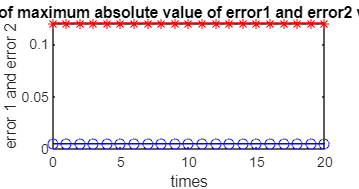


clf
figure(3);
plot(times,e1i,'*-r',times,e2i,'o-b');
title('Change of maximum absolute value of error1 and error2 with times i');
xlabel('times');ylabel('error 1 and error 2');

### 12.2 ILC Simulation for time-varying linear system

% The time-linear varying system is considered below
close all;
clear all;
figure(1)
imshow(imread("two_input_two_output_linear-system.png"));


% The ideal position of 2 joints is set as sin(3t) and cos(3t)
% To guarantee that outputs follow the ideal signals we choose
% CB = [2 2;0 1] and gamma = [0.95 0;0 0.95] and L = [2 0;0 2]
% psi = 0
% x(0) = [0;1]

%Adaptive switching Learning Control for 2 inputs and 2 outputs time
%varying linear system


%Iterative D-Type Learning Control
clear all;
close all;

t=[0:0.01:1]';
k(1:101)=0; %Total initial points
k=k';
T1(1:101)=0;
T1=T1';
T2=T1;
T=[T1 T2];

k1(1:101)=0; %Total initial points
k1=k1';
E1(1:101)=0;
E1=E1';
E2=E1;
E3=E1;
E4=E1;
E=[E1 E2 E3 E4];

% Closed loop PD control
% First see and run simulink file
% sim_control_two_input_two_output_linear_system.slx

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
x = out.x;
xd = out.xd;
E = out.E;
T = out.T;
t = out.t;

N = 50;
for i=0:1:N % Start Learning Control
    i;
    pause(0.01);
    
    sim('sim_control_two_input_two_output_linear_system',[0,1]);

    x1=x(:,1);
    x2=x(:,2);
    
    x1d=xd(:,1);
    x2d=xd(:,2);
    dx1d=xd(:,3);
    dx2d=xd(:,4);
    
    e1=E(:,1);
    e2=E(:,2);
    de1=E(:,3);
    de2=E(:,4);
    e=[e1 e2]';
    de=[de1 de2]';
    
    clf
    figure(1);
    subplot(211);
    hold on;
    plot(t,x1,'b',t,x1d,'r');
    xlabel('time(s)');ylabel('x1d,x1');
    subplot(212);
    hold on;
    plot(t,x2,'b',t,x2d,'r');
    xlabel('time(s)');ylabel('x2d,x2');
    
    j=i+1;
    times(j)=i;
    e1i(j)=max(abs(e1));
    e2i(j)=max(abs(e2));
    de1i(j)=max(abs(de1));
    de2i(j)=max(abs(de2));
end %End of i

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
sgtitle('Closed loop PD control')


clf
figure(2);
subplot(211);
plot(t,x1d,'r',t,x1,'b');
xlabel('time(s)');ylabel('Position tracking of x1');
subplot(212);
plot(t,x2d,'r',t,x2,'b');
xlabel('time(s)');ylabel('Position tracking of x2');
sgtitle('Closed loop PD control')


clf
figure(3);
subplot(211);
plot(t,T(:,1),'r');
xlabel('time(s)');ylabel('Control input 1');
subplot(212);
plot(t,T(:,2),'r');
xlabel('time(s)');ylabel('Control input 2');
sgtitle('Closed loop PD control')


clf
figure(4);
plot(times,e1i,'*-r',times,e2i,'o-b');
title('Change of maximum absolute value of error1 and error2 with times');
xlabel('times');ylabel('error 1 and error 2');

% Open loop PD control
% First see and run simulink file
% sim_control_two_input_two_output_linear_system.slx

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
x = out.x;
xd = out.xd;
E = out.E;
T = out.T;
t = out.t;

N = 30;
for i=0:1:N % Start Learning Control
    i;
    pause(0.01);
    
    sim('sim_control_two_input_two_output_linear_system',[0,1]);

    x1=x(:,1);
    x2=x(:,2);
    
    x1d=xd(:,1);
    x2d=xd(:,2);
    dx1d=xd(:,3);
    dx2d=xd(:,4);
    
    e1=E(:,1);
    e2=E(:,2);
    de1=E(:,3);
    de2=E(:,4);
    e=[e1 e2]';
    de=[de1 de2]';
    
    figure(1)
    subplot(211);
    hold on;
    plot(t,x1,'b',t,x1d,'r');
    xlabel('time(s)');ylabel('x1d,x1');
    subplot(212);
    hold on;
    plot(t,x2,'b',t,x2d,'r');
    xlabel('time(s)');ylabel('x2d,x2');
    hold on
    
    j=i+1;
    times(j)=i;
    e1i(j)=max(abs(e1));
    e2i(j)=max(abs(e2));
    de1i(j)=max(abs(de1));
    de2i(j)=max(abs(de2));
end %End of i

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
sgtitle('Open loop PD control')


clf
figure(2);
subplot(211);
plot(t,x1d,'r',t,x1,'b');
xlabel('time(s)');ylabel('Position tracking of x1');
subplot(212);
plot(t,x2d,'r',t,x2,'b');
xlabel('time(s)');ylabel('Position tracking of x2');
sgtitle('Open loop PD control')


clf
figure(3);
subplot(211);
plot(t,T(:,1),'r');
xlabel('time(s)');ylabel('Control input 1');
subplot(212);
plot(t,T(:,2),'r');
xlabel('time(s)');ylabel('Control input 2');
sgtitle('Open loop PD control')


clf
figure(4);
plot(times,e1i,'*-r',times,e2i,'o-b');
title('Change of maximum absolute value of error1 and error2 with times');
xlabel('times');ylabel('error 1 and error 2');